# Lab 3 

## Init

clear;

## R1.a)

[signal, fs] = audioread('fugee.wav');
fs

fs = 8000

signal = signal(1:end-1);
soundsc(signal,fs);

clear sound;

The signal plays a song ("Killing me softly with his song") with audible sharp noises identified at particular time instants (possibly the same noise as it is heard in grafonolas :)).

## R1.b)

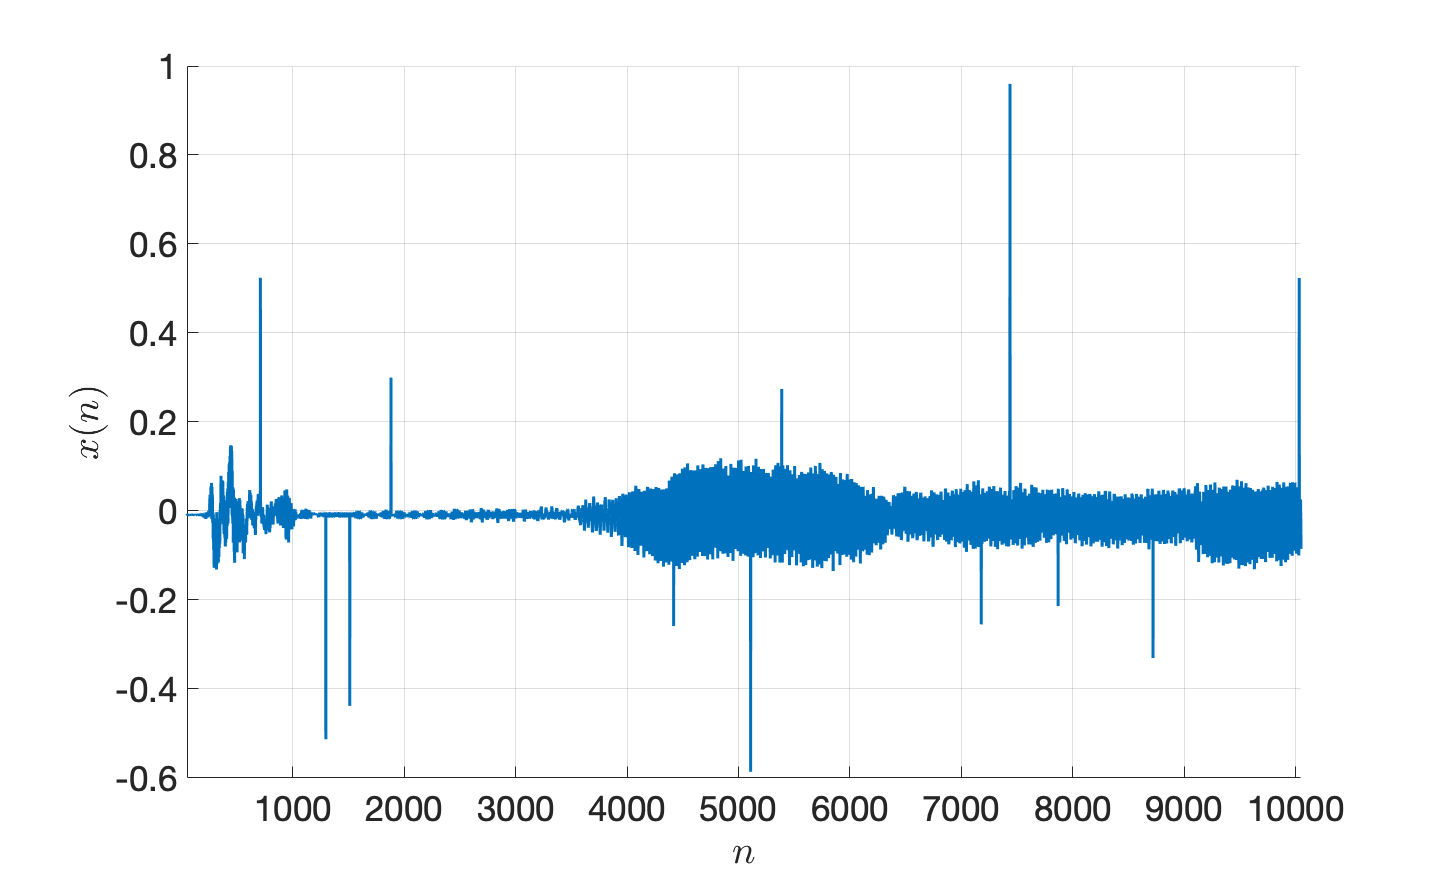

ti = 50;%length(signal)/2;
Nsamples = 10000; 
figure('units','normalized','outerposition',[0 0 1 1]);
hold on;
grid on;
set(gca,'FontSize',35);
xlabel("$n$",'Interpreter','latex');
ylabel("$x(n)$",'Interpreter','latex');
plot(ti:ti+Nsamples-1,signal(ti:ti+Nsamples-1),'LineWidth',3);
xlim([ti ti+Nsamples-1]);
saveas(gcf,'./figures/R1b.png');

The sharp noises pointed out previously are very noticeable in the plot above. Ruido impulsivo

## R1.c)

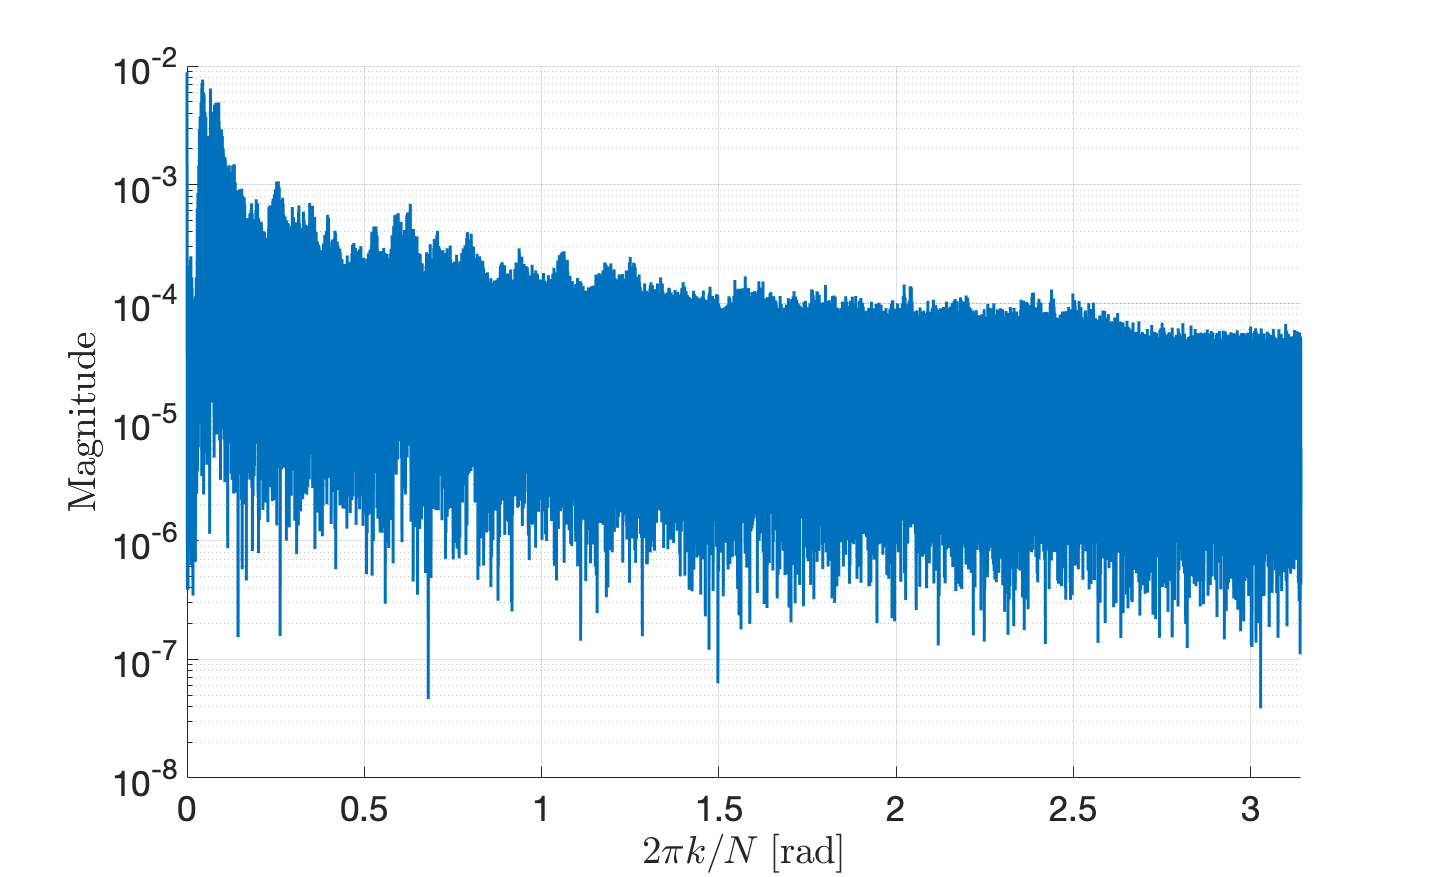

[absX,~,wX] = dft_custom(signal,length(signal));
% Plot |X(k)|
figure('units','normalized','outerposition',[0 0 1 1]);
hold on;
grid on;
xlabel("$2\pi k/N \;[\mathrm{rad}]$",'Interpreter','latex');
ylabel("Magnitude",'Interpreter','latex');
set(gca,'FontSize',35);
plot(wX,absX,'LineWidth',3);
set(gca,'Yscale','log');
xlim([min(wX) max(wX)]);
saveas(gcf,'./figures/R1c.png');

The sharp noises are not easily identified in the magnitude spectrum. -> Dizer ainda que um filtro de frequencia não parace ser o mais indicado -> ruido impulsivo tem espetro conatnte na frequencia ão é possivel observar o seu impacto na frequencia 

## R2.a)

butterOrder = 10;
wco = pi/2;
fco =  wco/(2*pi*1/fs)

fco = 2.0000e+03

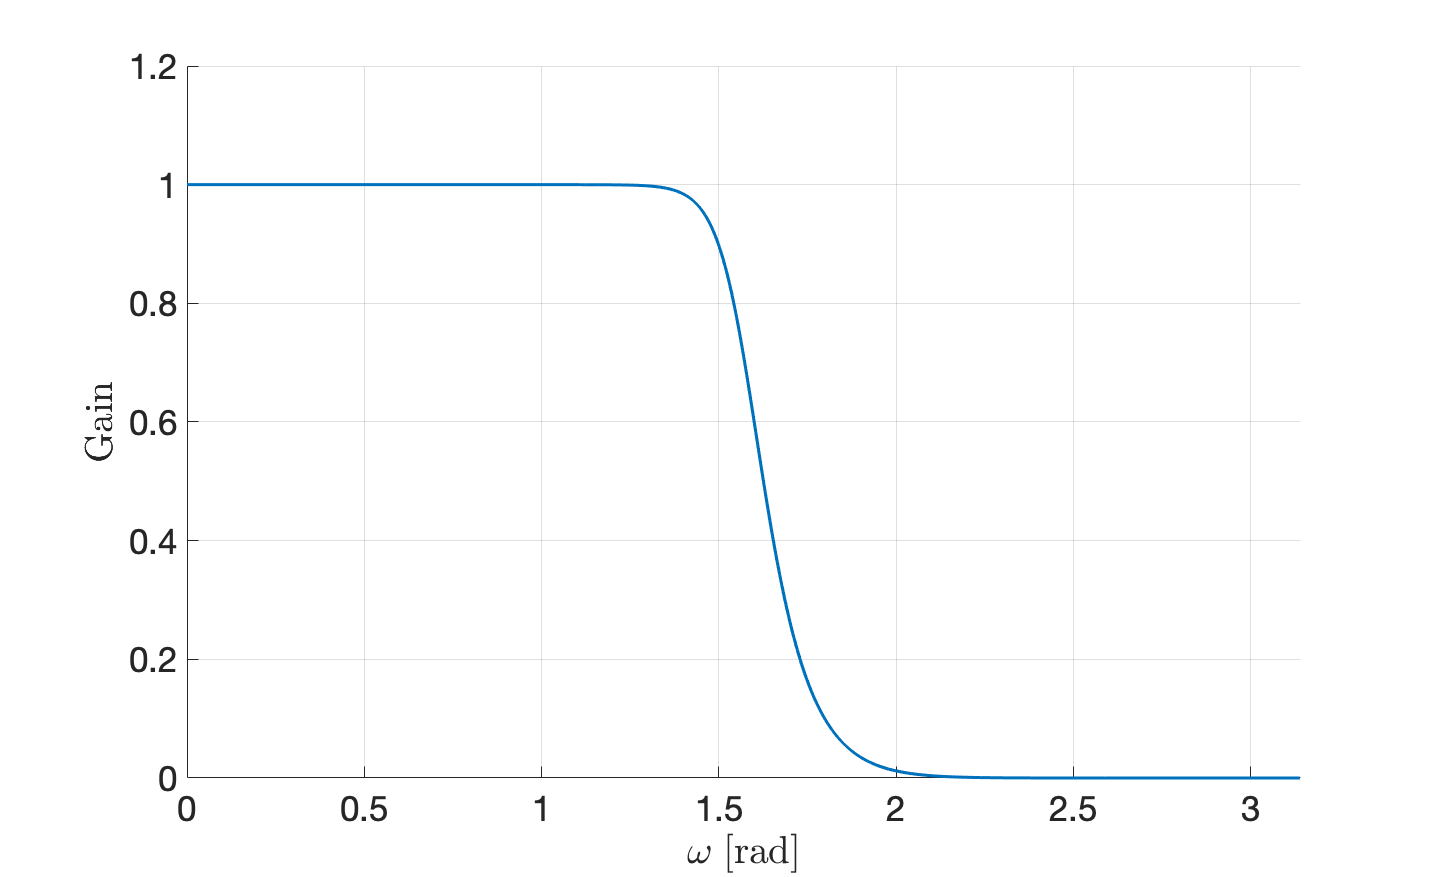

Wn = 2*fco/fs; % Normalised cutoff frequency
[bLTI,aLTI] = butter(butterOrder,2*fco/fs,'low');
[h,w] = freqz(bLTI,aLTI,1e3); 
% Plot |X(k)|
figure('units','normalized','outerposition',[0 0 1 1]);
hold on;
grid on;
xlabel("$\omega \;[\mathrm{rad}]$",'Interpreter','latex');
ylabel("Gain",'Interpreter','latex');
set(gca,'FontSize',35);
plot(w,abs(h),'LineWidth',3);
%%set(gca,'Yscale','log');
xlim([min(wX) max(wX)]);
saveas(gcf,'./figures/R2a.png'); %% phase

The gain is unitary for low frequency and decreases for high frequencies stating at the cutoff frequency.

## R2.b)

signalLTIfilter = filter(bLTI,aLTI,signal);
fco

fco = 2.0000e+03

## R2.c)

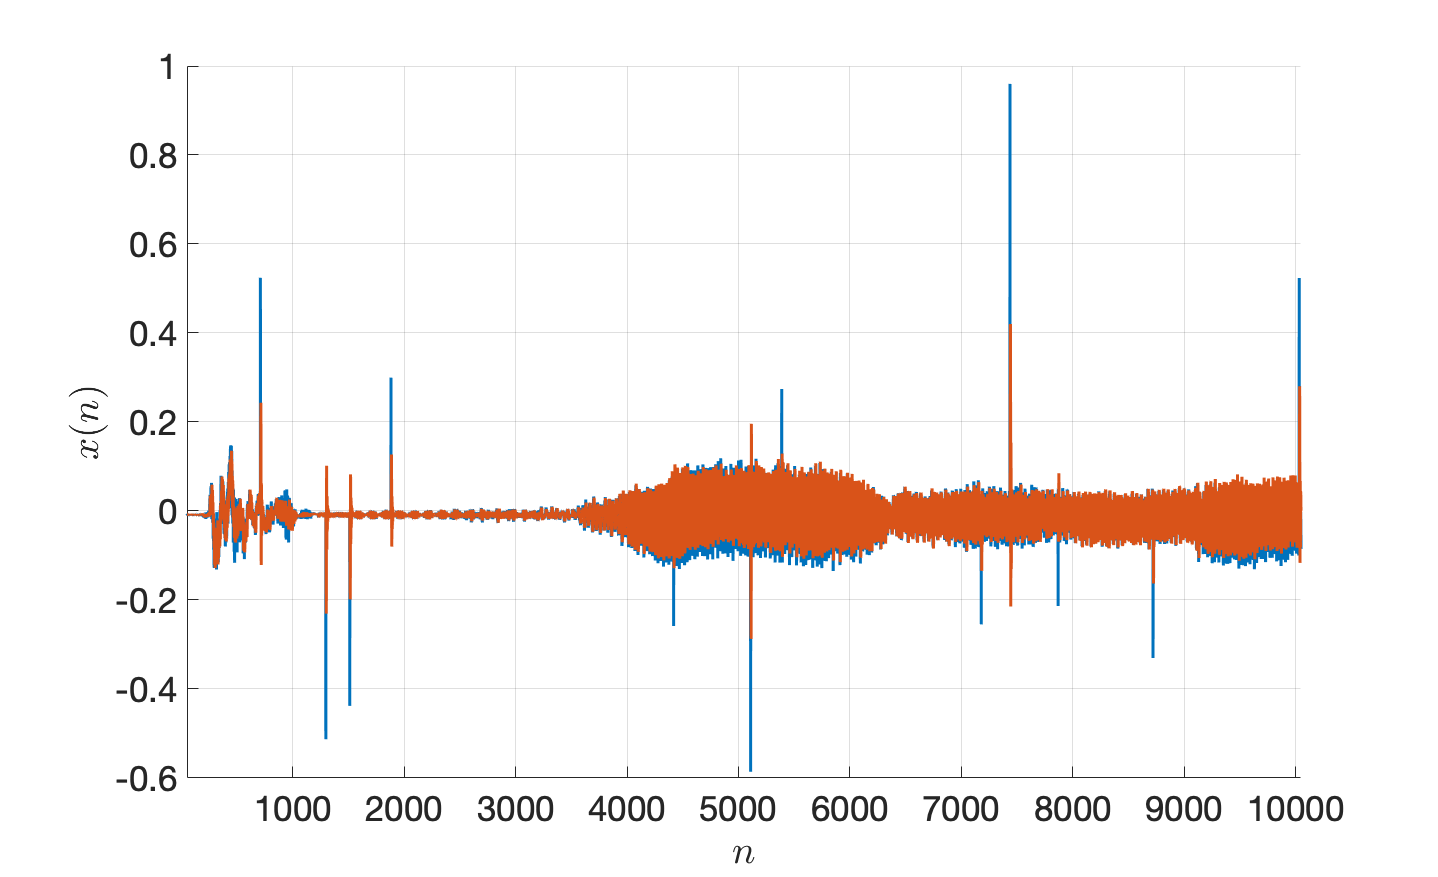

ti = 50;%length(signal)/2;
Nsamples = 10000; 
figure('units','normalized','outerposition',[0 0 1 1]);
hold on;
grid on;
set(gca,'FontSize',35);
xlabel("$n$",'Interpreter','latex');
ylabel("$x(n)$",'Interpreter','latex');
plot(ti:ti+Nsamples-1,signal(ti:ti+Nsamples-1),'LineWidth',3);
plot(ti:ti+Nsamples-1,signalLTIfilter(ti:ti+Nsamples-1),'LineWidth',3);
xlim([ti ti+Nsamples-1]);
saveas(gcf,'./figures/R2c.png');

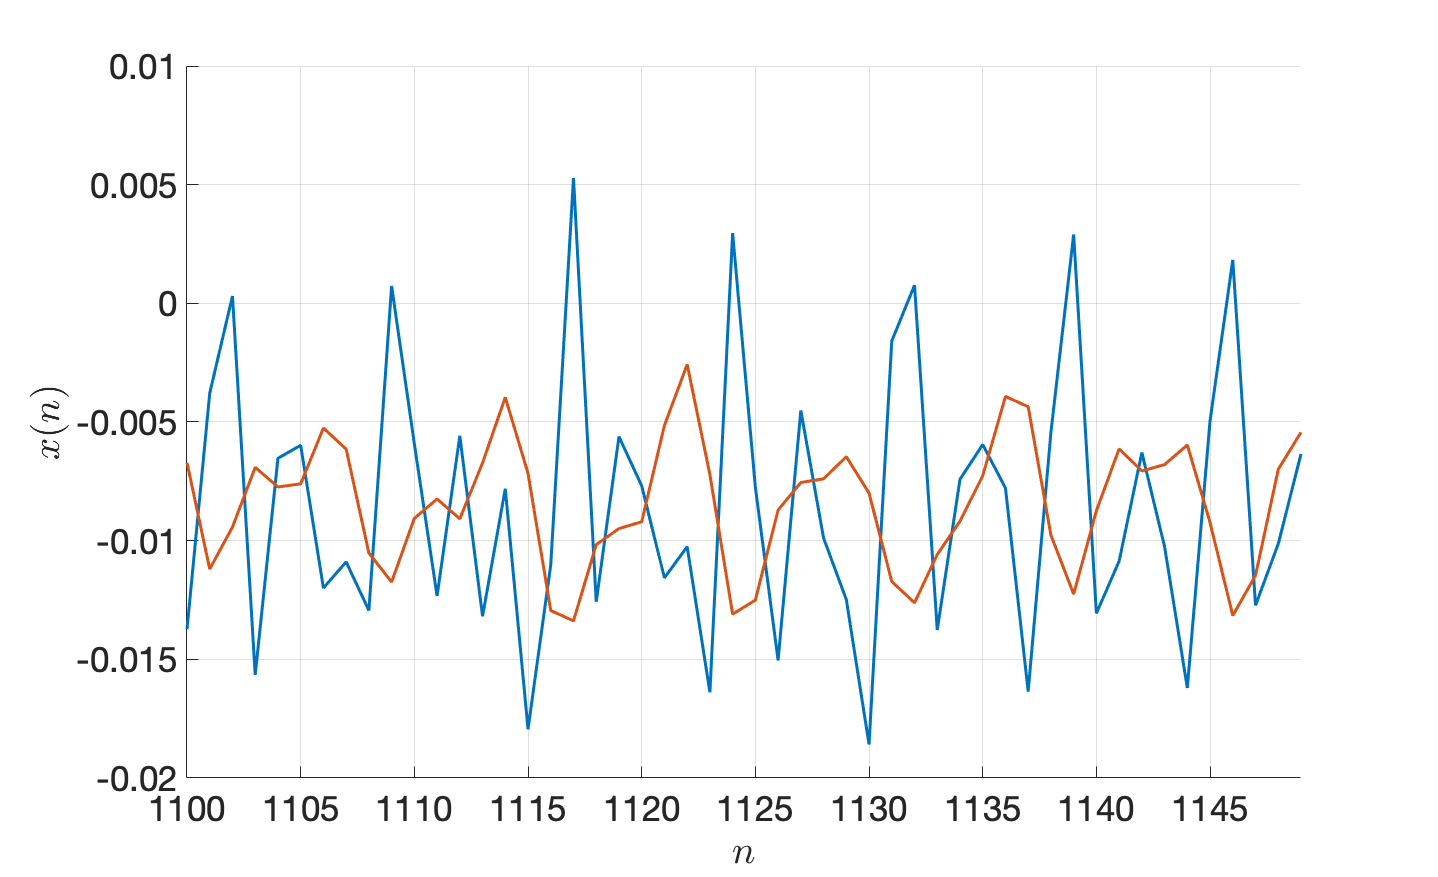

ti = 1100;%length(signal)/2;
Nsamples = 50; 
figure('units','normalized','outerposition',[0 0 1 1]);
hold on;
grid on;
set(gca,'FontSize',35);
xlabel("$n$",'Interpreter','latex');
ylabel("$x(n)$",'Interpreter','latex');
plot(ti:ti+Nsamples-1,signal(ti:ti+Nsamples-1),'LineWidth',3);
plot(ti:ti+Nsamples-1,signalLTIfilter(ti:ti+Nsamples-1),'LineWidth',3);
xlim([ti ti+Nsamples-1]);
saveas(gcf,'./figures/R2c_smallAmp.png');

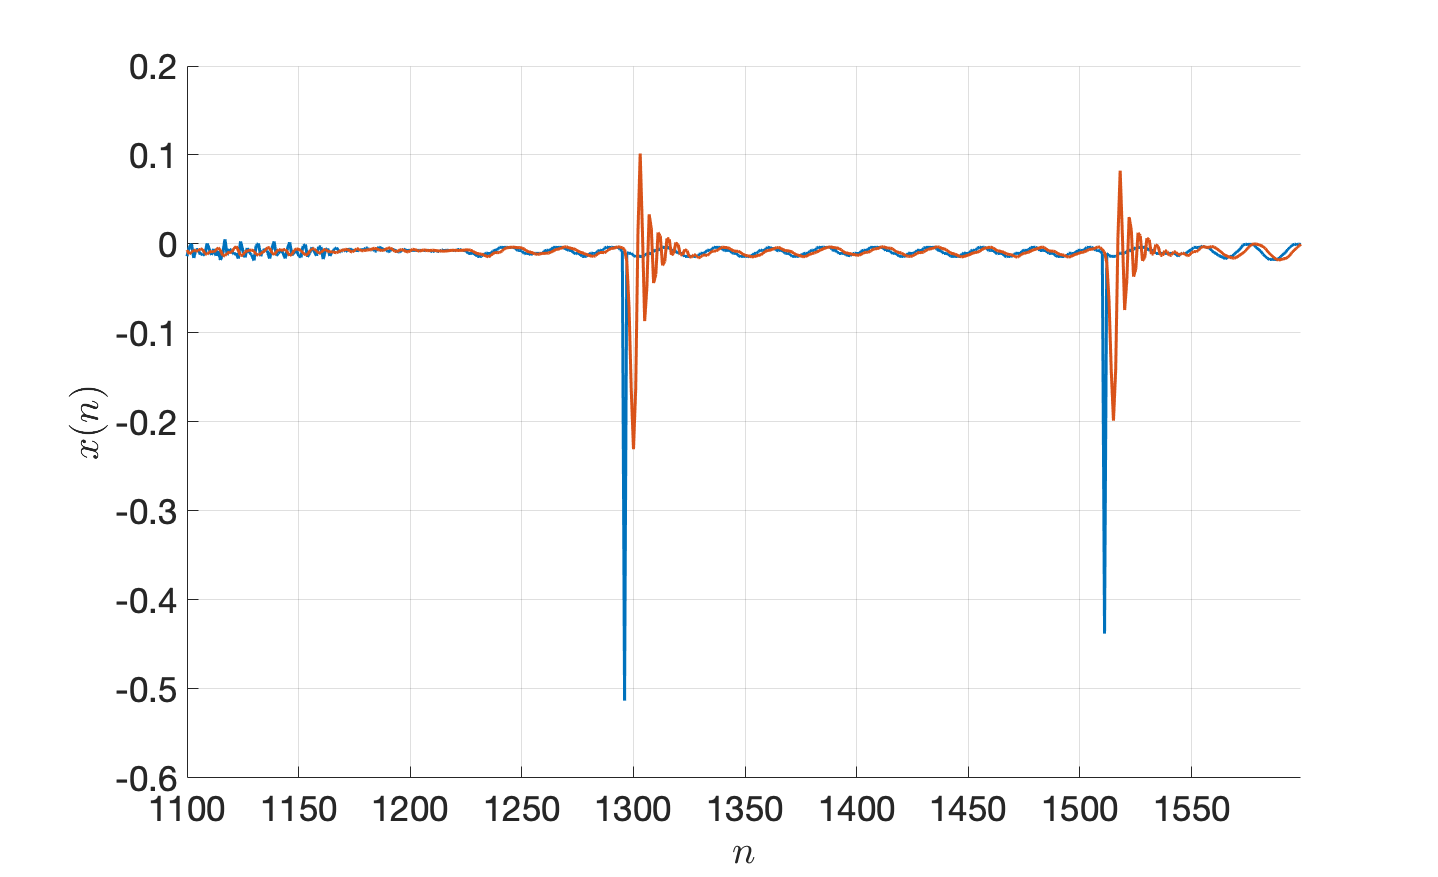

ti = 1100;%length(signal)/2;
Nsamples = 500; 
figure('units','normalized','outerposition',[0 0 1 1]);
hold on;
grid on;
set(gca,'FontSize',35);
xlabel("$n$",'Interpreter','latex');
ylabel("$x(n)$",'Interpreter','latex');
plot(ti:ti+Nsamples-1,signal(ti:ti+Nsamples-1),'LineWidth',3);
plot(ti:ti+Nsamples-1,signalLTIfilter(ti:ti+Nsamples-1),'LineWidth',3);
xlim([ti ti+Nsamples-1]);
saveas(gcf,'./figures/R2c_zoomNoise.png');

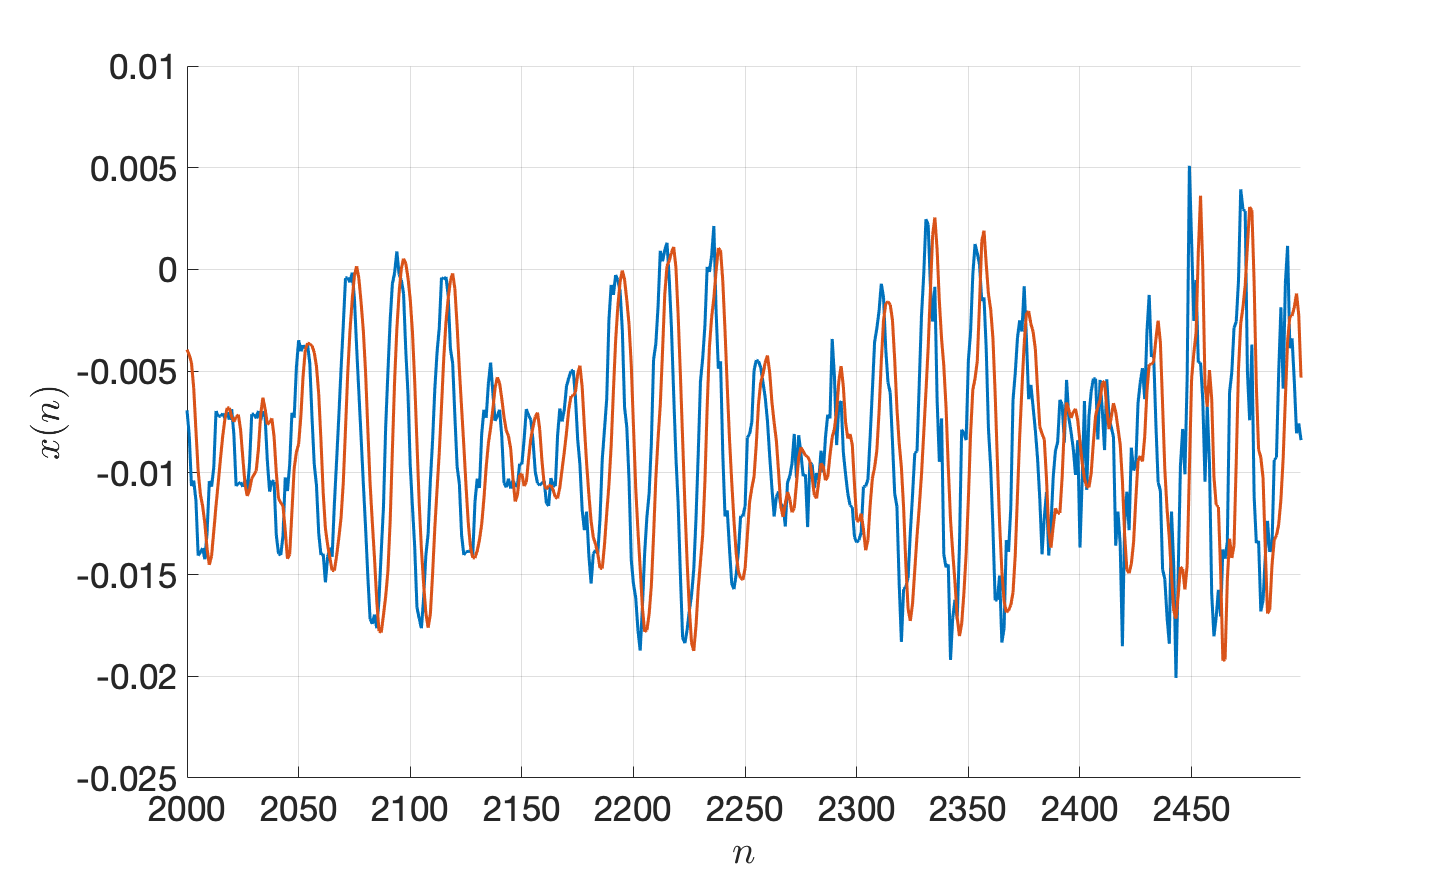

ti = 2000;%length(signal)/2; % parecido com sistema de segunad order subamortecido -> nao estamos a tirar os impoulso -> atenua em freq nao em a seguir aos ruidos aperece a resposta ao impulso do sistema 
Nsamples = 500; 
figure('units','normalized','outerposition',[0 0 1 1]);
hold on;
grid on;
set(gca,'FontSize',35);
xlabel("$n$",'Interpreter','latex');
ylabel("$x(n)$",'Interpreter','latex');
plot(ti:ti+Nsamples-1,signal(ti:ti+Nsamples-1),'LineWidth',3);
plot(ti:ti+Nsamples-1,signalLTIfilter(ti:ti+Nsamples-1),'LineWidth',3);
xlim([ti ti+Nsamples-1]);
saveas(gcf,'./figures/R2c_zoomNormal.png');

The sharp noise bursts are attenuated, as seen in the first plot. However, as seen in the second plot it distorts low amplitude regions. Third, although it atenuates the sharp noises, it the oscilates a lot. Fourth, the signal is delayed in time, depending on the freqeuncy, which causes loss of sharpness and small distortion. -> delay distorcido pela fase

## R2.d)

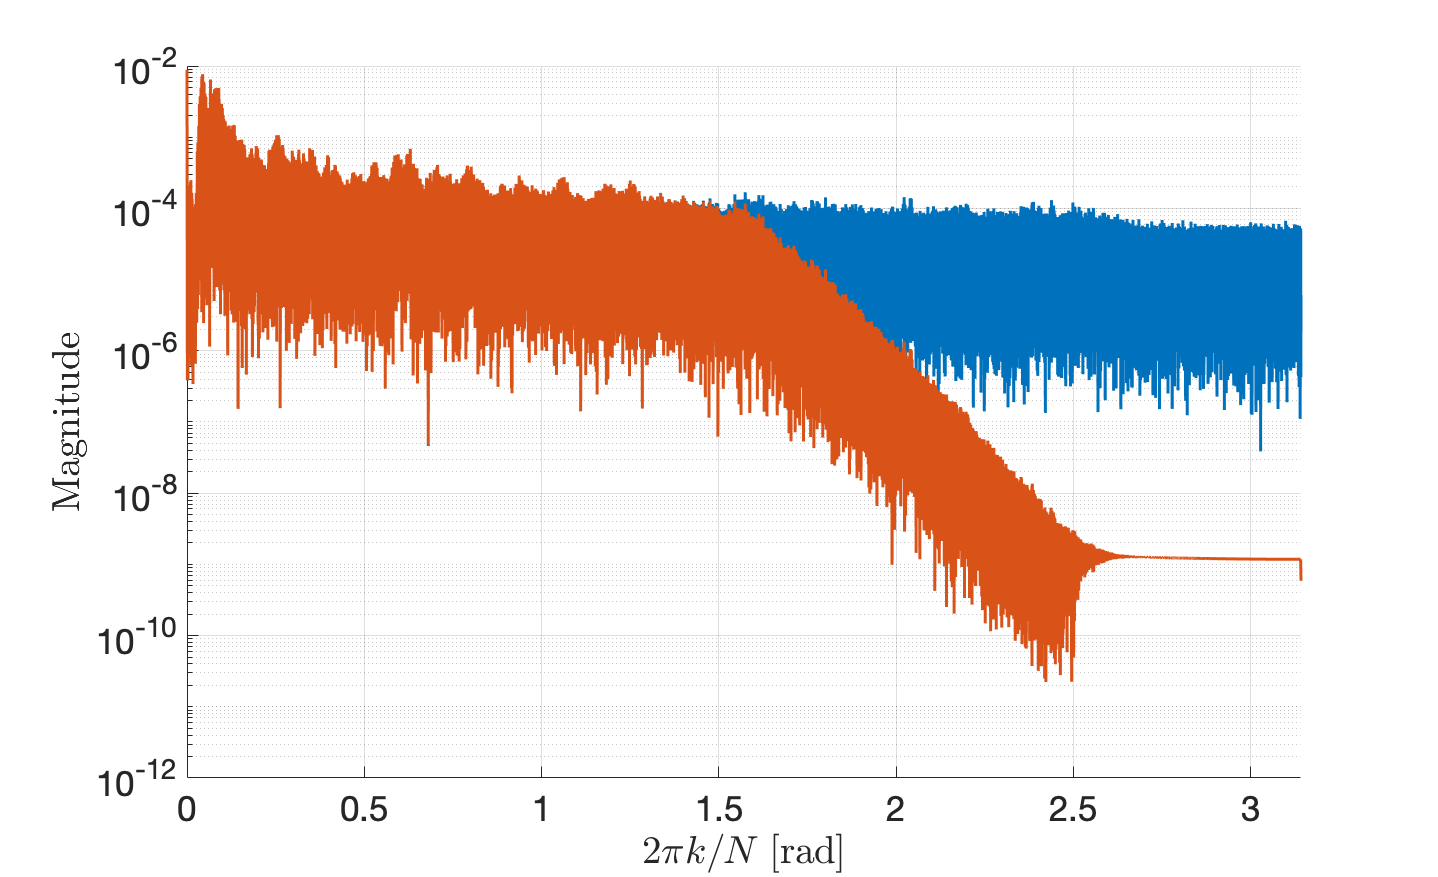

[absXLTIfilter,~,wXLTIfilter] = dft_custom(signalLTIfilter,length(signalLTIfilter));
% Plot |X(k)|
figure('units','normalized','outerposition',[0 0 1 1]);
hold on;
grid on;
xlabel("$2\pi k/N \;[\mathrm{rad}]$",'Interpreter','latex');
ylabel("Magnitude",'Interpreter','latex');
set(gca,'FontSize',35);
plot(wX,absX,'LineWidth',3);
plot(wXLTIfilter,absXLTIfilter,'LineWidth',3);
set(gca,'Yscale','log');
xlim([min(wX) max(wX)]);
saveas(gcf,'./figures/R2d.png');

The high frequeency components of the signal are indiscrimidenately attenuated. It it very noticeable for frequencues higher than the cutoff frequency.

## R2.e)

soundsc(signalLTIfilter,fs);

clear sound;

Although the sharp noises are somewhat attenuated, they are stil very noticeable.

## R2.f)

butterOrder = 10;
wco = pi/4;
fco =  wco/(2*pi*1/fs)

fco = 1.0000e+03

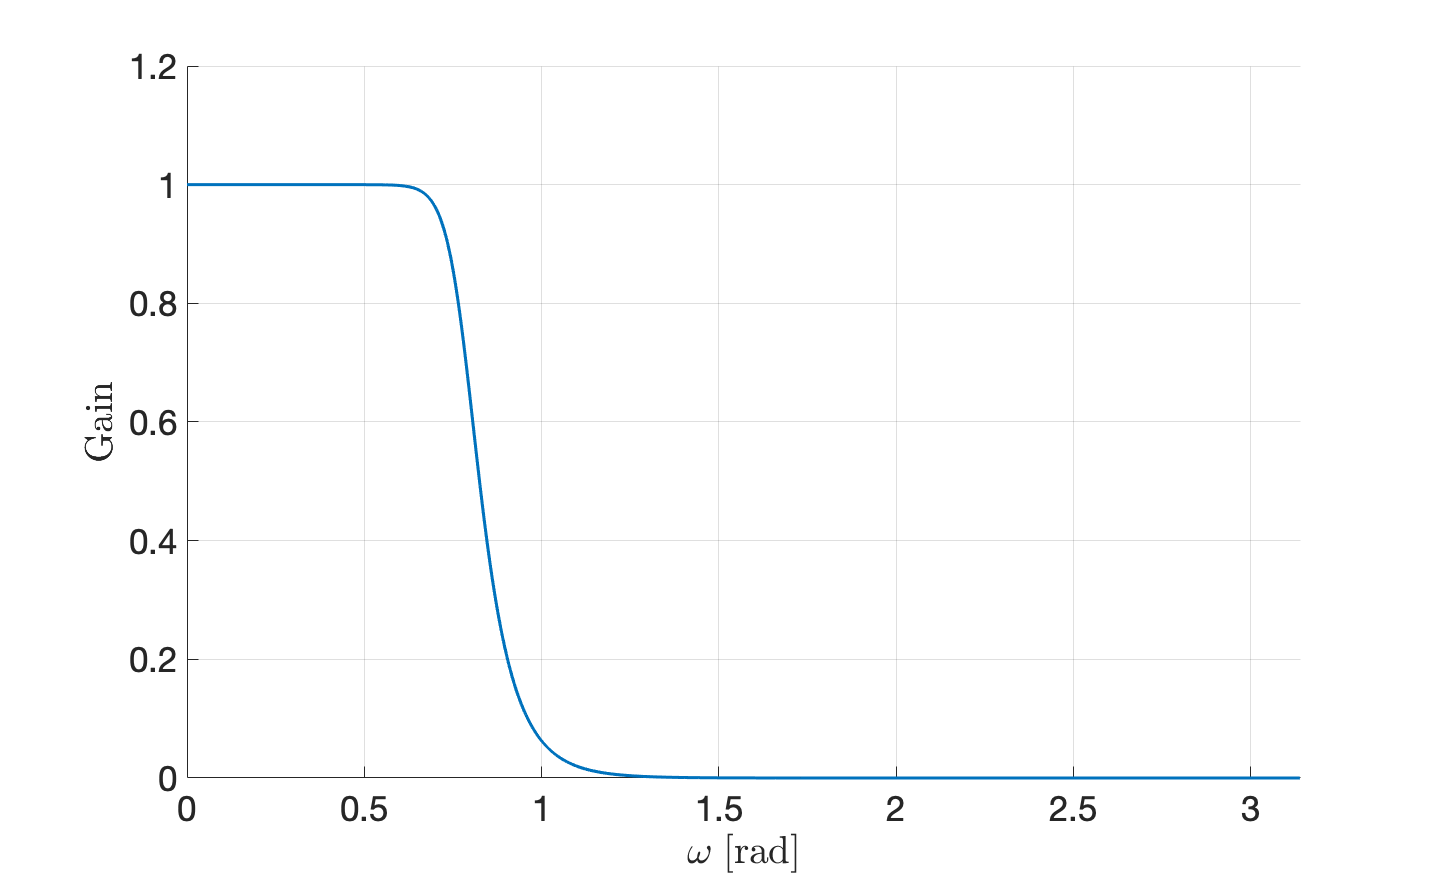

Wn = 2*fco/fs; % Normalised cutoff frequency
[bLTI,aLTI] = butter(butterOrder,2*fco/fs,'low');
[h,w] = freqz(bLTI,aLTI,1e3); 
% Plot |X(k)|
figure('units','normalized','outerposition',[0 0 1 1]);
hold on;
grid on;
xlabel("$\omega \;[\mathrm{rad}]$",'Interpreter','latex');
ylabel("Gain",'Interpreter','latex');
set(gca,'FontSize',35);
plot(w,abs(h),'LineWidth',3);
%%set(gca,'Yscale','log');
xlim([min(wX) max(wX)]);
saveas(gcf,'./figures/R2f_filter.png');

signalLTIfilter = filter(bLTI,aLTI,signal);
fco

fco = 1.0000e+03

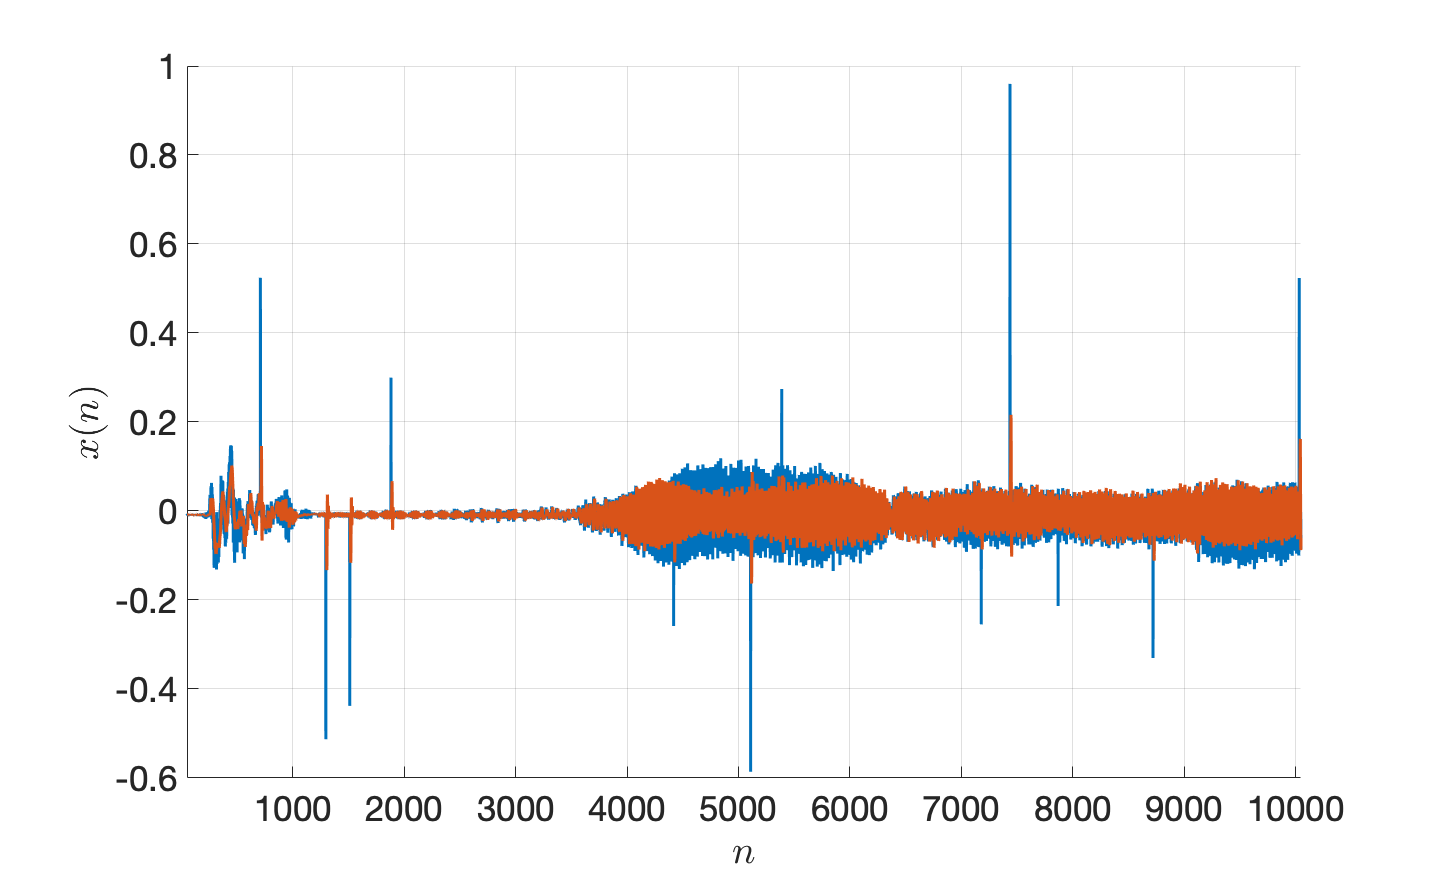

ti = 50;%length(signal)/2;
Nsamples = 10000; 
figure('units','normalized','outerposition',[0 0 1 1]);
hold on;
grid on;
set(gca,'FontSize',35);
xlabel("$n$",'Interpreter','latex');
ylabel("$x(n)$",'Interpreter','latex');
plot(ti:ti+Nsamples-1,signal(ti:ti+Nsamples-1),'LineWidth',3);
plot(ti:ti+Nsamples-1,signalLTIfilter(ti:ti+Nsamples-1),'LineWidth',3);
xlim([ti ti+Nsamples-1]);
saveas(gcf,'./figures/R2f_zoomOut.png');

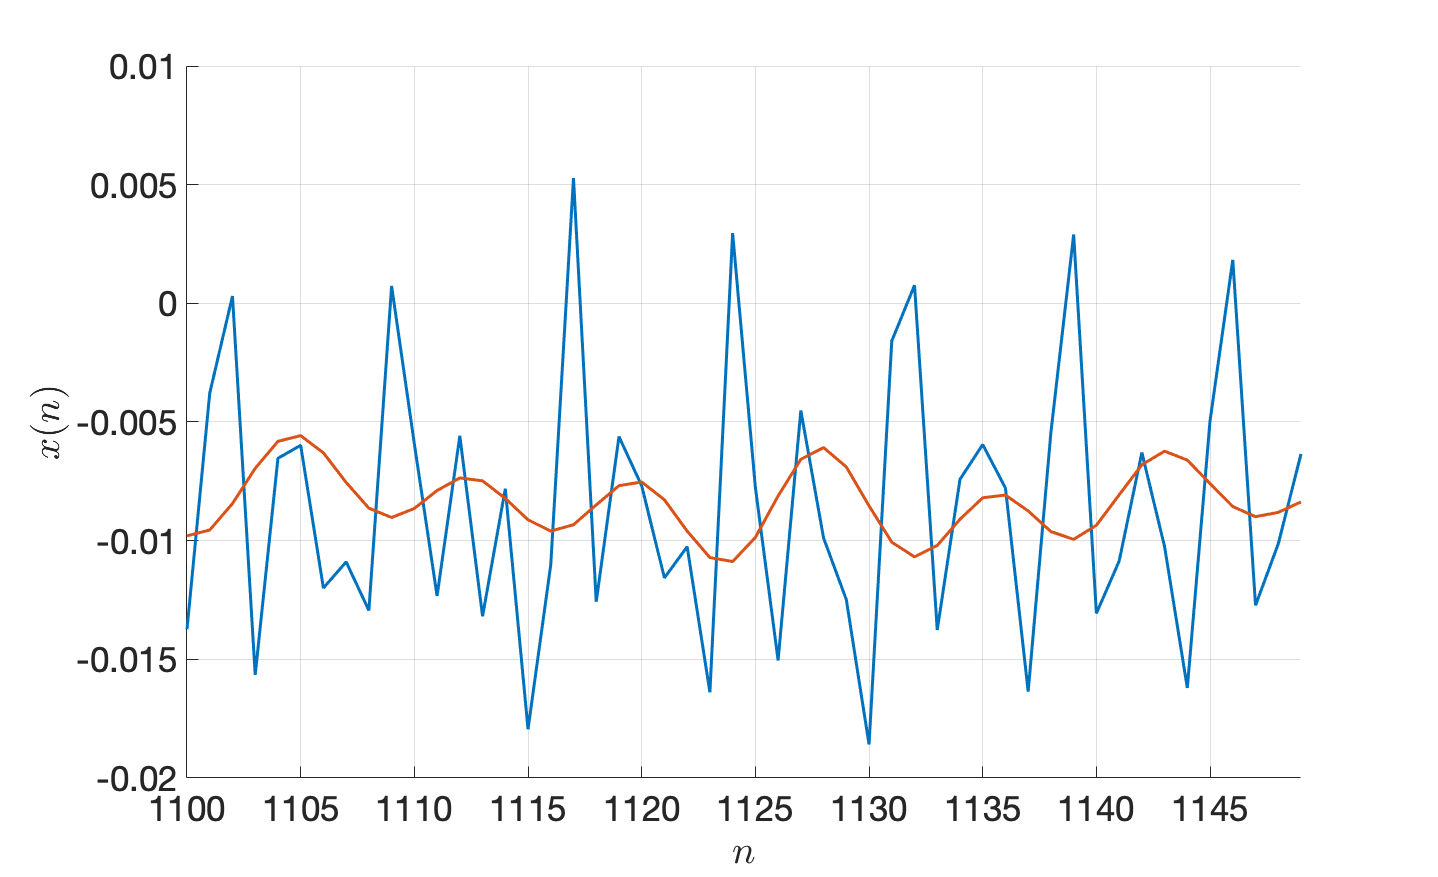

ti = 1100;%length(signal)/2;
Nsamples = 50; 
figure('units','normalized','outerposition',[0 0 1 1]);
hold on;
grid on;
set(gca,'FontSize',35);
xlabel("$n$",'Interpreter','latex');
ylabel("$x(n)$",'Interpreter','latex');
plot(ti:ti+Nsamples-1,signal(ti:ti+Nsamples-1),'LineWidth',3);
plot(ti:ti+Nsamples-1,signalLTIfilter(ti:ti+Nsamples-1),'LineWidth',3);
xlim([ti ti+Nsamples-1]);
saveas(gcf,'./figures/R2f_smallAmp.png');

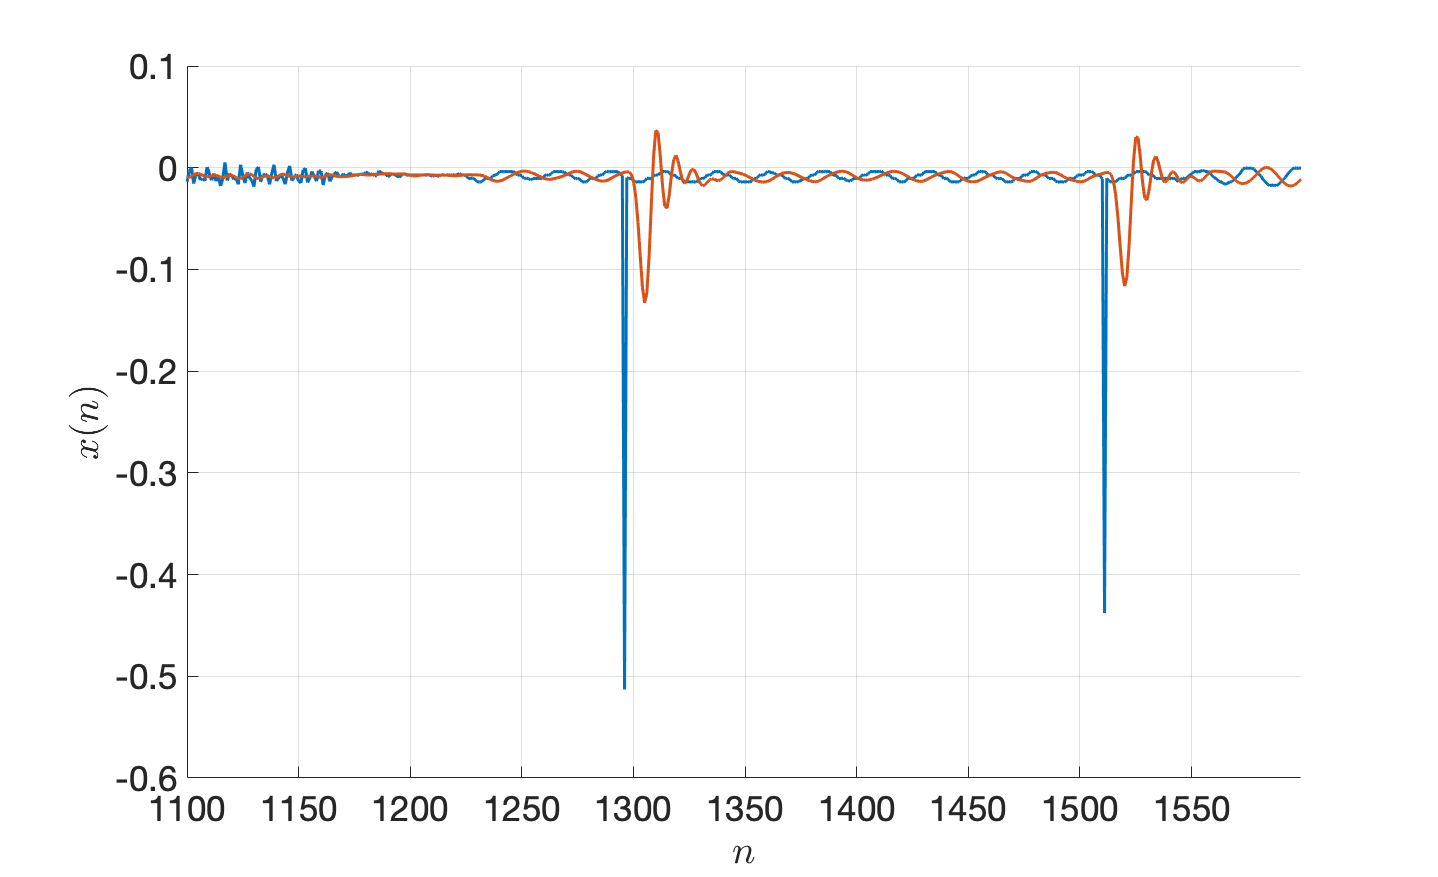

ti = 1100;%length(signal)/2;
Nsamples = 500; 
figure('units','normalized','outerposition',[0 0 1 1]);
hold on;
grid on;
set(gca,'FontSize',35);
xlabel("$n$",'Interpreter','latex');
ylabel("$x(n)$",'Interpreter','latex');
plot(ti:ti+Nsamples-1,signal(ti:ti+Nsamples-1),'LineWidth',3);
plot(ti:ti+Nsamples-1,signalLTIfilter(ti:ti+Nsamples-1),'LineWidth',3);
xlim([ti ti+Nsamples-1]);
saveas(gcf,'./figures/R2f_zoomNoise.png');

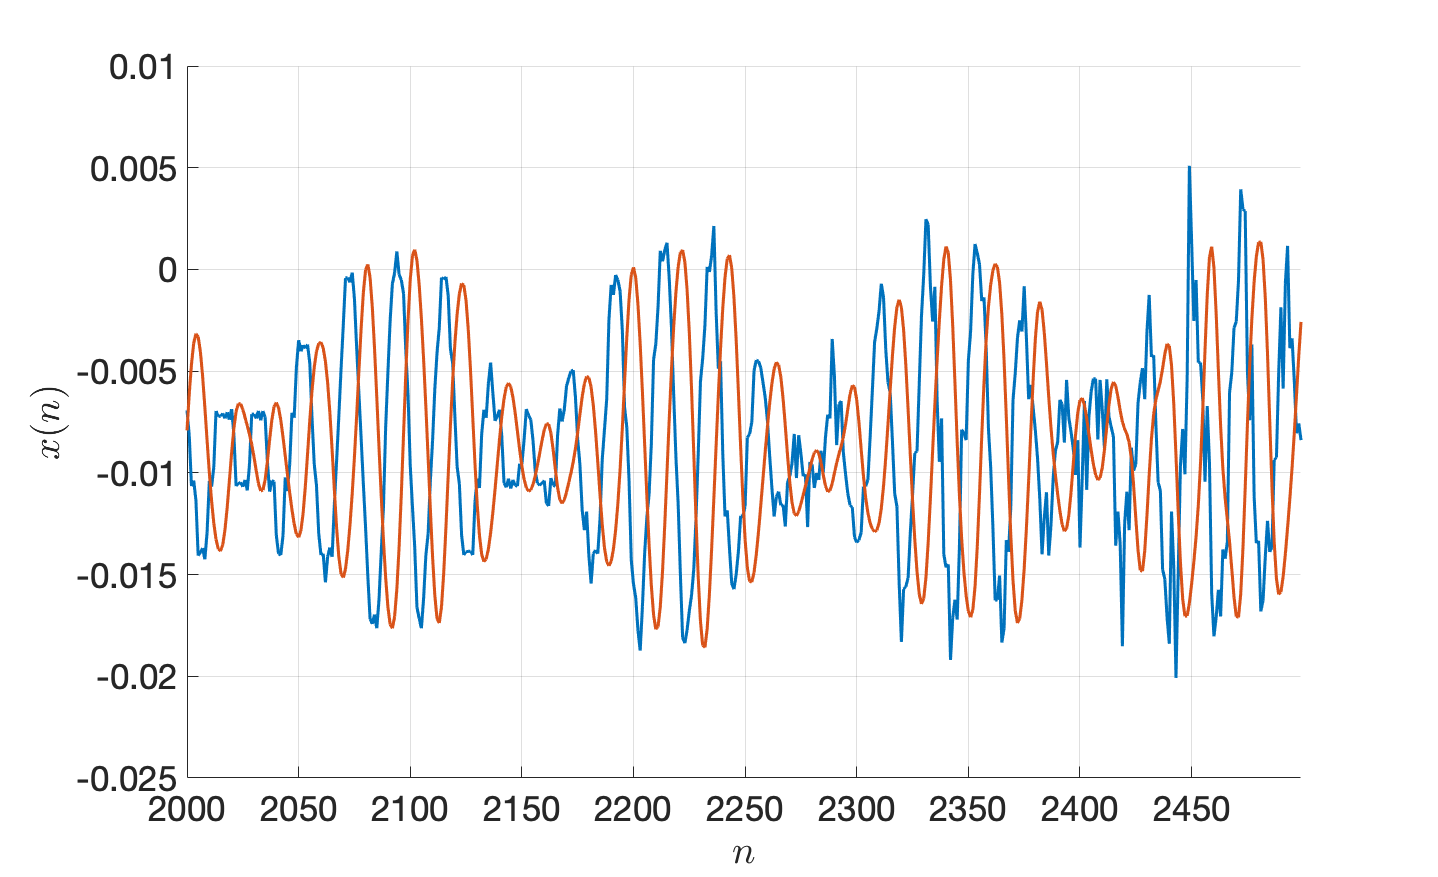

ti = 2000;%length(signal)/2;
Nsamples = 500; 
figure('units','normalized','outerposition',[0 0 1 1]);
hold on;
grid on;
set(gca,'FontSize',35);
xlabel("$n$",'Interpreter','latex');
ylabel("$x(n)$",'Interpreter','latex');
plot(ti:ti+Nsamples-1,signal(ti:ti+Nsamples-1),'LineWidth',3);
plot(ti:ti+Nsamples-1,signalLTIfilter(ti:ti+Nsamples-1),'LineWidth',3);
xlim([ti ti+Nsamples-1]);
saveas(gcf,'./figures/R2f_zoomNormal.png');

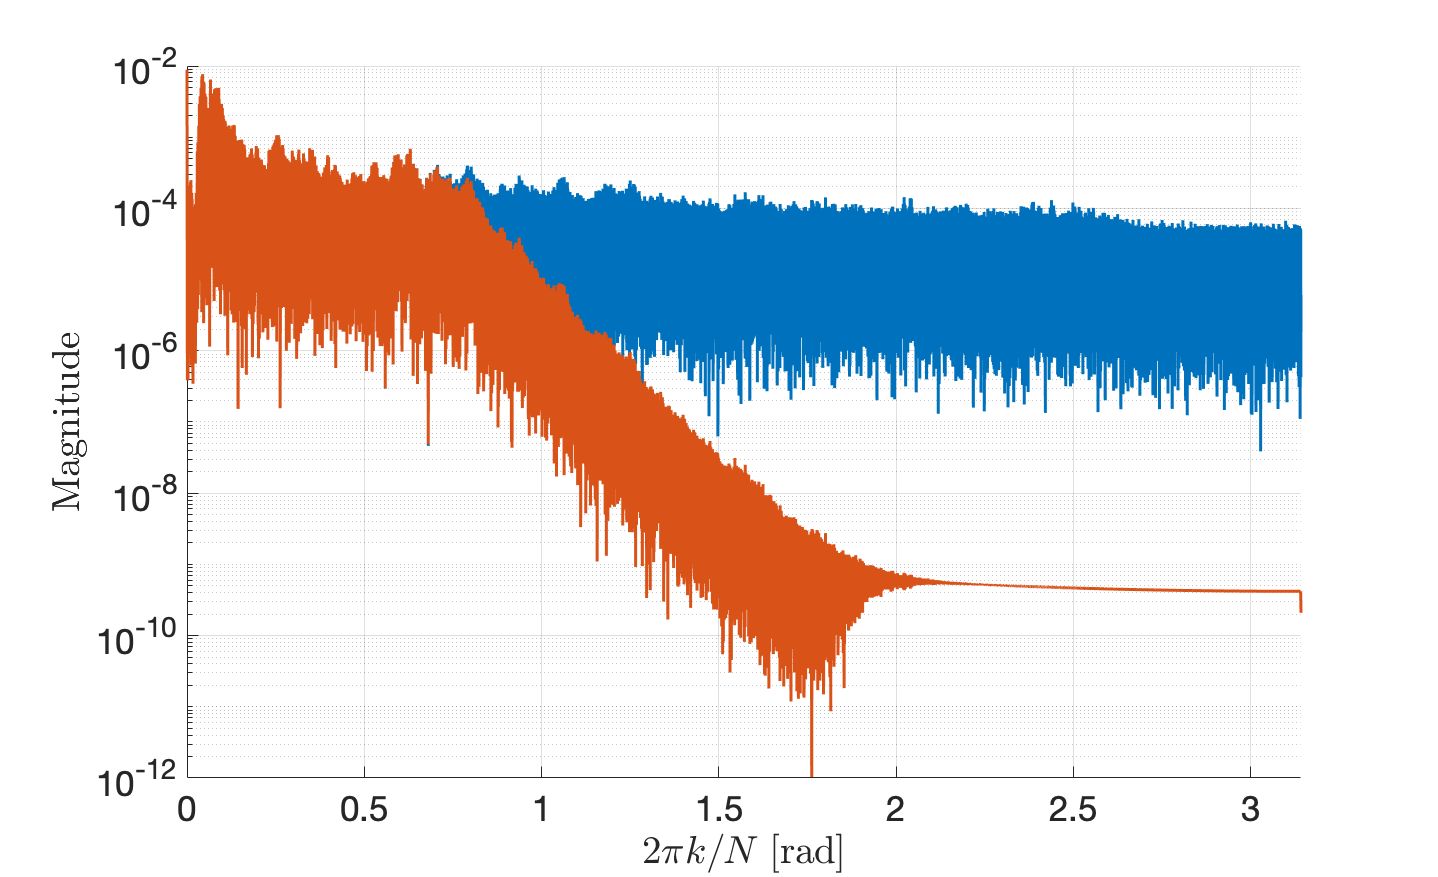

[absXLTIfilter,~,wXLTIfilter] = dft_custom(signalLTIfilter,length(signalLTIfilter));
% Plot |X(k)|
figure('units','normalized','outerposition',[0 0 1 1]);
hold on;
grid on;
xlabel("$2\pi k/N \;[\mathrm{rad}]$",'Interpreter','latex');
ylabel("Magnitude",'Interpreter','latex');
set(gca,'FontSize',35);
plot(wX,absX,'LineWidth',3);
plot(wXLTIfilter,absXLTIfilter,'LineWidth',3);
set(gca,'Yscale','log');
xlim([min(wX) max(wX)]);
saveas(gcf,'./figures/R2f_spectra.png');

soundsc(signalLTIfilter,fs);

clear sound;

It is possible to attenuate even more the sharp noises decreasing the cutoff frequency. However, the song loses sharpness.

## R3.a)

Non-causal, BIBO stable, nonlinear, time invariant 

## R3.b)

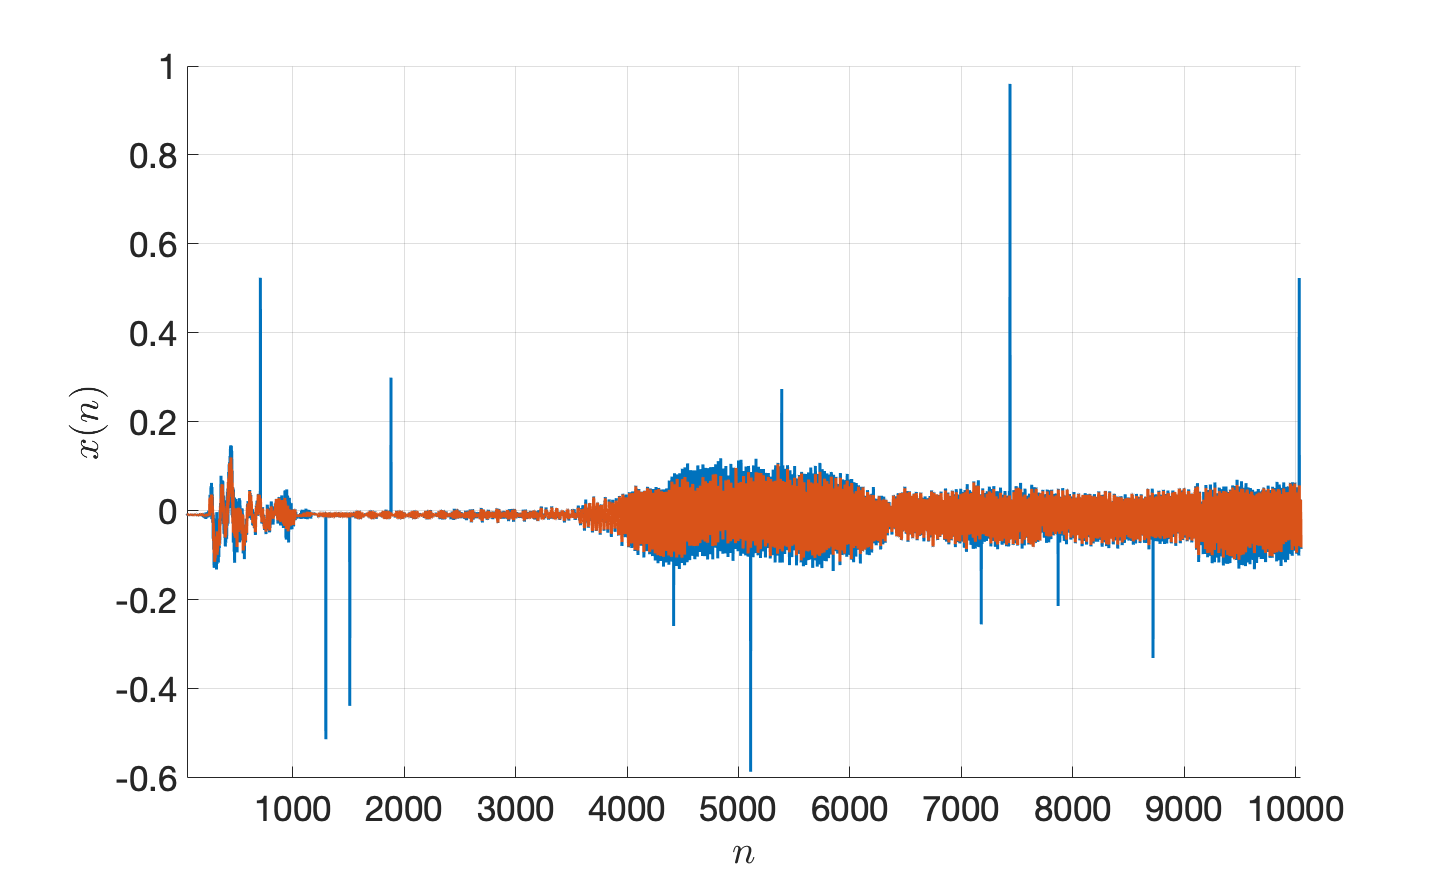

signalMedianfilter = medfilt1(signal);
ti = 50;%length(signal)/2;
Nsamples = 10000; 
figure('units','normalized','outerposition',[0 0 1 1]);
hold on;
grid on;
set(gca,'FontSize',35);
xlabel("$n$",'Interpreter','latex');
ylabel("$x(n)$",'Interpreter','latex');
plot(ti:ti+Nsamples-1,signal(ti:ti+Nsamples-1),'LineWidth',3);
plot(ti:ti+Nsamples-1,signalMedianfilter(ti:ti+Nsamples-1),'LineWidth',3);
xlim([ti ti+Nsamples-1]);
saveas(gcf,'./figures/R3b_zoomOut.png');

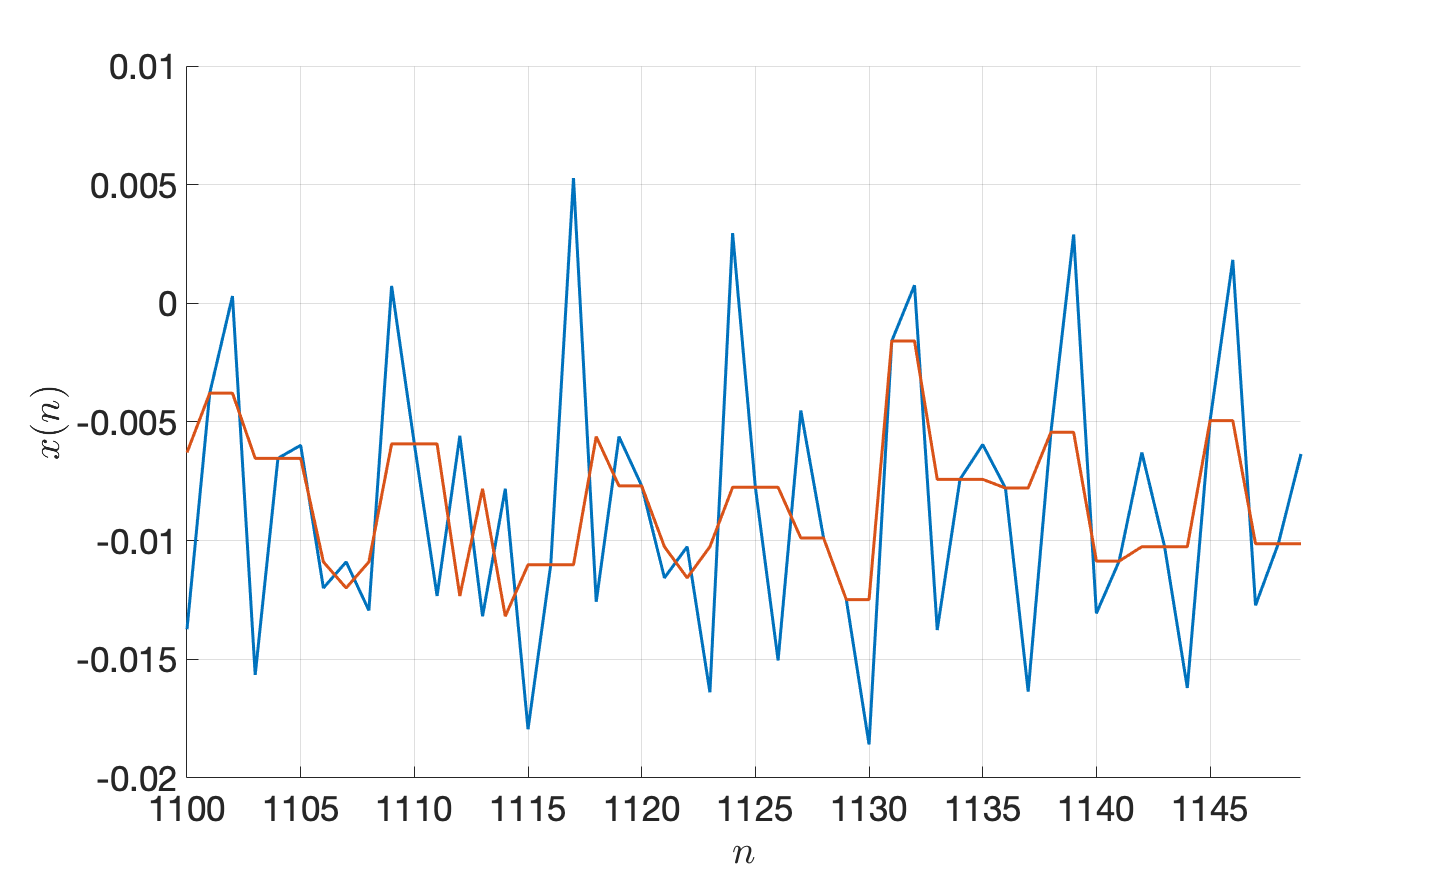

ti = 1100;%length(signal)/2;
Nsamples = 50; 
figure('units','normalized','outerposition',[0 0 1 1]);
hold on;
grid on;
set(gca,'FontSize',35);
xlabel("$n$",'Interpreter','latex');
ylabel("$x(n)$",'Interpreter','latex');
plot(ti:ti+Nsamples-1,signal(ti:ti+Nsamples-1),'LineWidth',3);
plot(ti:ti+Nsamples-1,signalMedianfilter(ti:ti+Nsamples-1),'LineWidth',3);
xlim([ti ti+Nsamples-1]);
saveas(gcf,'./figures/R3b_smallAmp.png');

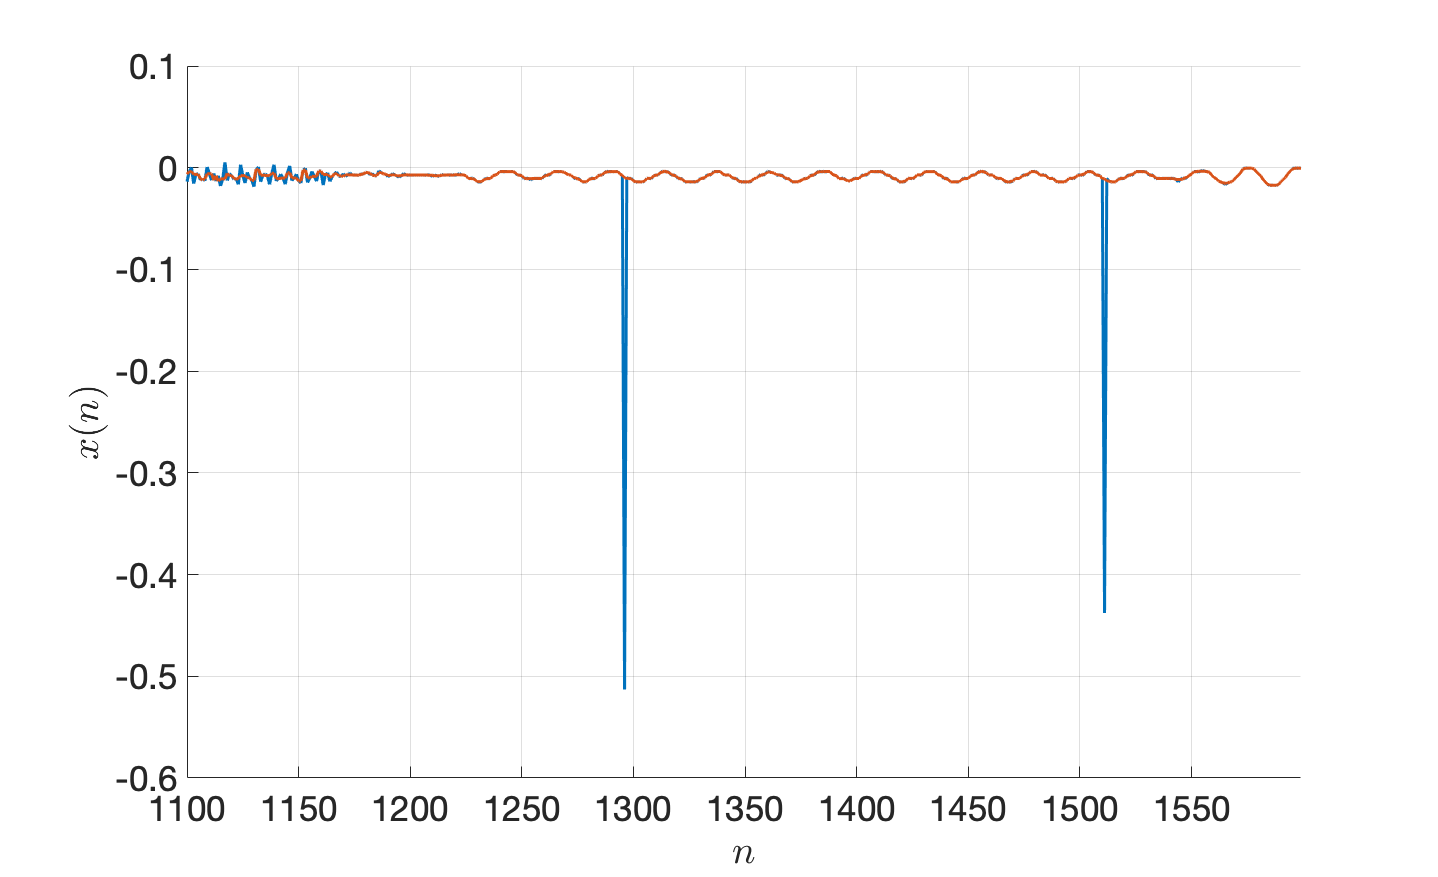

ti = 1100;%length(signal)/2; -> stetrogram f vs t
Nsamples = 500; 
figure('units','normalized','outerposition',[0 0 1 1]);
hold on;
grid on;
set(gca,'FontSize',35);
xlabel("$n$",'Interpreter','latex');
ylabel("$x(n)$",'Interpreter','latex');
plot(ti:ti+Nsamples-1,signal(ti:ti+Nsamples-1),'LineWidth',3);
plot(ti:ti+Nsamples-1,signalMedianfilter(ti:ti+Nsamples-1),'LineWidth',3);
xlim([ti ti+Nsamples-1]);
saveas(gcf,'./figures/R3b_zoomNoise.png');

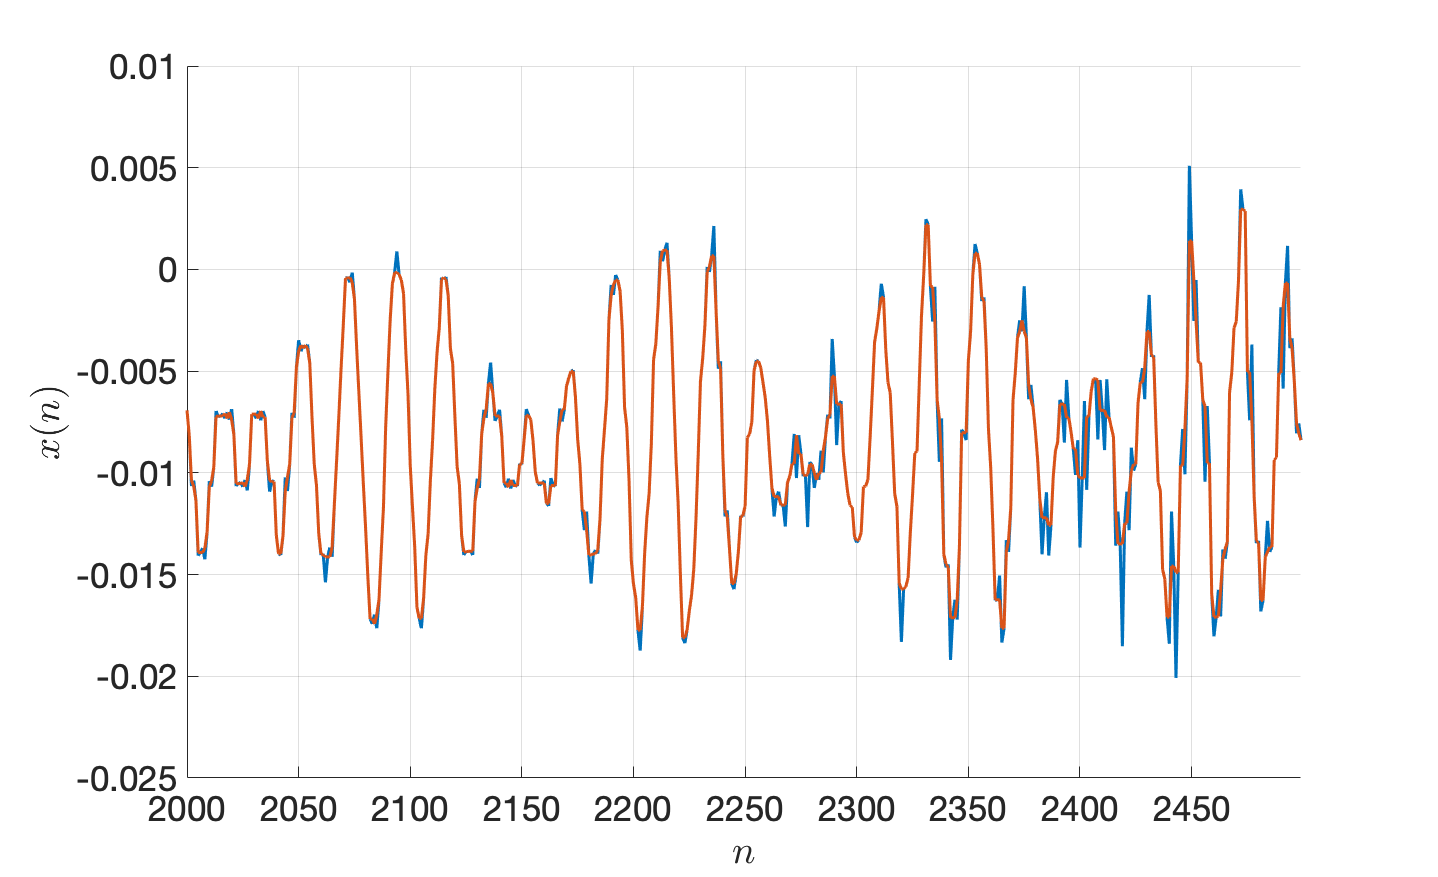

ti = 2000;%length(signal)/2;
Nsamples = 500; 
figure('units','normalized','outerposition',[0 0 1 1]);
hold on;
grid on;
set(gca,'FontSize',35);
xlabel("$n$",'Interpreter','latex');
ylabel("$x(n)$",'Interpreter','latex');
plot(ti:ti+Nsamples-1,signal(ti:ti+Nsamples-1),'LineWidth',3);
plot(ti:ti+Nsamples-1,signalMedianfilter(ti:ti+Nsamples-1),'LineWidth',3);
xlim([ti ti+Nsamples-1]);
saveas(gcf,'./figures/R3b_zoomNormal.png');

First, the sharp noises are very attenuated, much more than the LTI filter. Second, low aplitude regions are somewhat distorted, but not as much as in the LTI filter. Third, there are no vivible oscilations due to the sharp noises. Fourth, there is no delay. Not, however, that this filter is not causal, thus if it is applied online it as a delay of two samples.

## R3.c)

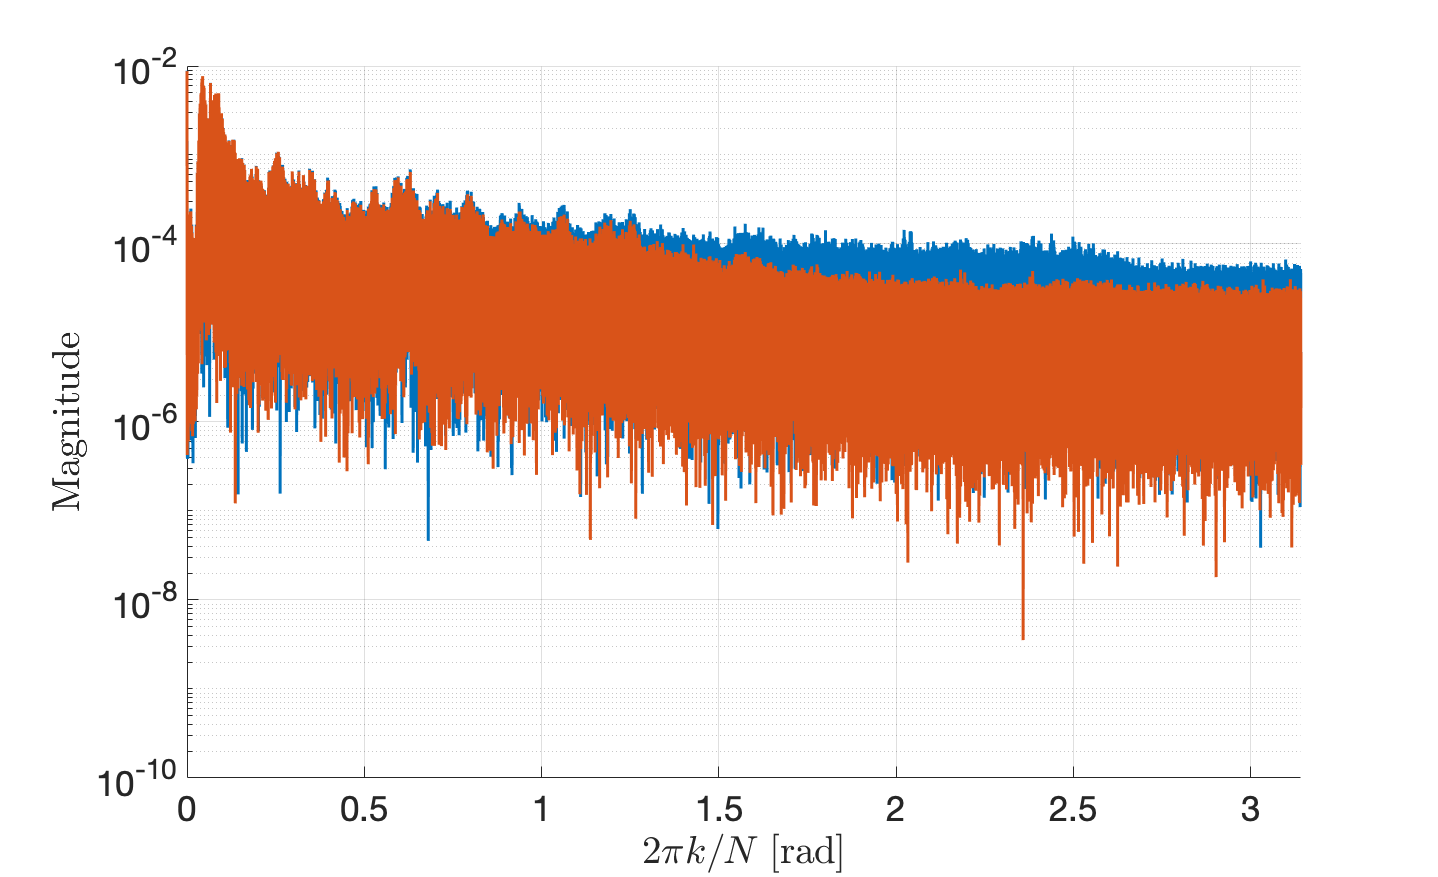

[absXMedianfilter,~,wXMedianfilter] = dft_custom(signalMedianfilter,length(signalMedianfilter));
% Plot |X(k)|
figure('units','normalized','outerposition',[0 0 1 1]);
hold on;
grid on;
xlabel("$2\pi k/N \;[\mathrm{rad}]$",'Interpreter','latex');
ylabel("Magnitude",'Interpreter','latex');
set(gca,'FontSize',35);
plot(wX,absX,'LineWidth',3);
plot(wXMedianfilter,absXMedianfilter,'LineWidth',3);
set(gca,'Yscale','log');
xlim([min(wX) max(wX)]);
saveas(gcf,'./figures/R3c.png'); %% strectrogram 1 lab

The median filter does not attenuate considerably high frequencies. It is as if, due to the characteristics of the noise, the median filter attenuates the frequencies of the noise, mantaining th high frequencies of the song, which contributes to the sharpness of the filtered signal.

## R3.d)

soundsc(signalMedianfilter,fs);

clear sound;

The sharp noises are no longer heard. There is, however, some loss of sharpness noticeable, especially for low amplitude zones.

## R3.e)

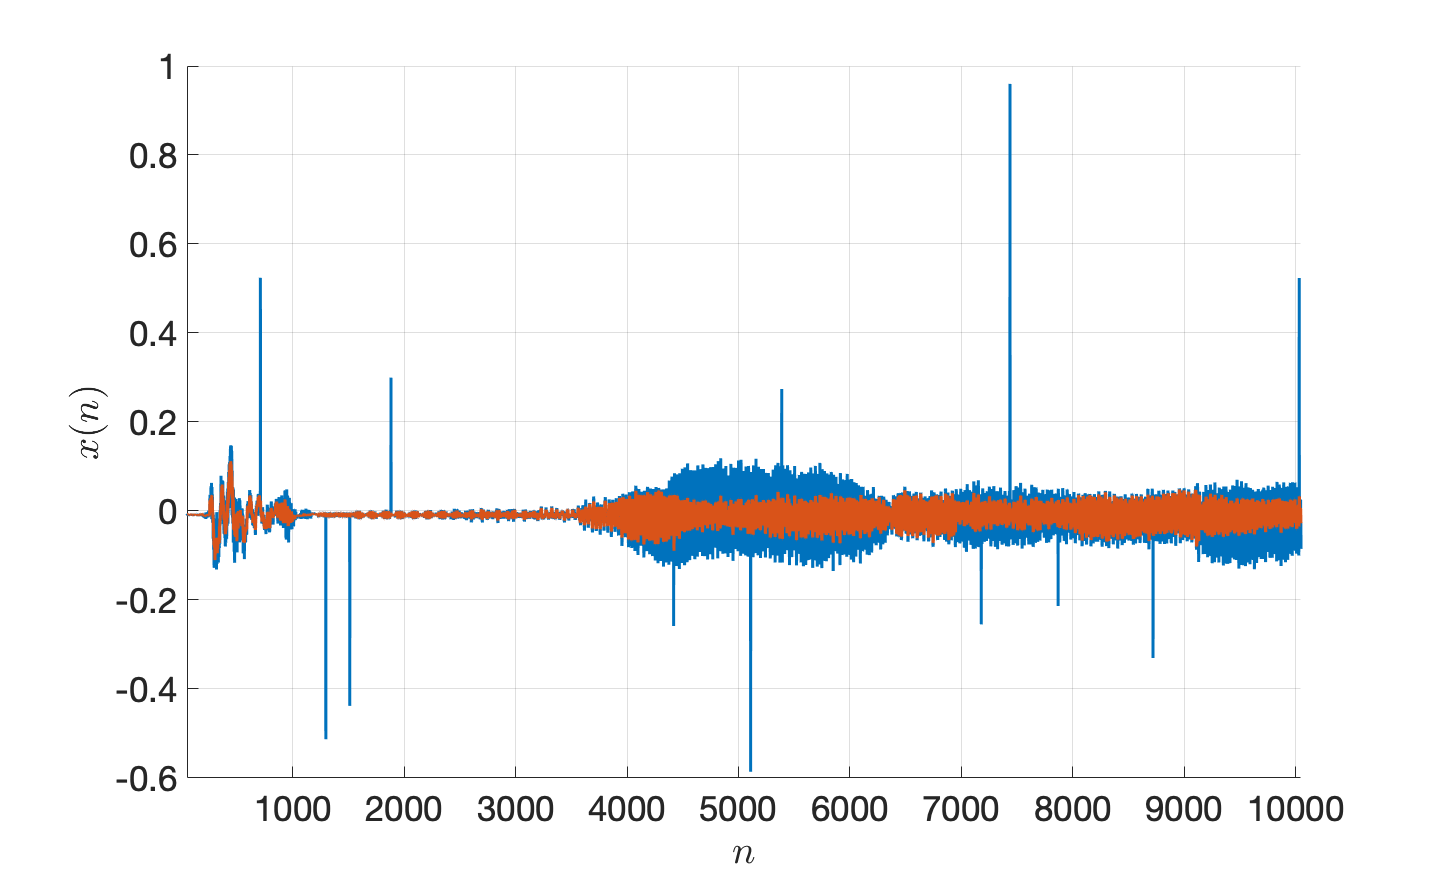

medianOrder = 6;
signalMedianfilter = medfilt1(signal,medianOrder);
ti = 50;%length(signal)/2;
Nsamples = 10000; 
figure('units','normalized','outerposition',[0 0 1 1]);
hold on;
grid on;
set(gca,'FontSize',35);
xlabel("$n$",'Interpreter','latex');
ylabel("$x(n)$",'Interpreter','latex');
plot(ti:ti+Nsamples-1,signal(ti:ti+Nsamples-1),'LineWidth',3);
plot(ti:ti+Nsamples-1,signalMedianfilter(ti:ti+Nsamples-1),'LineWidth',3);
xlim([ti ti+Nsamples-1]);
saveas(gcf,'./figures/R3e_zoomOut.png');

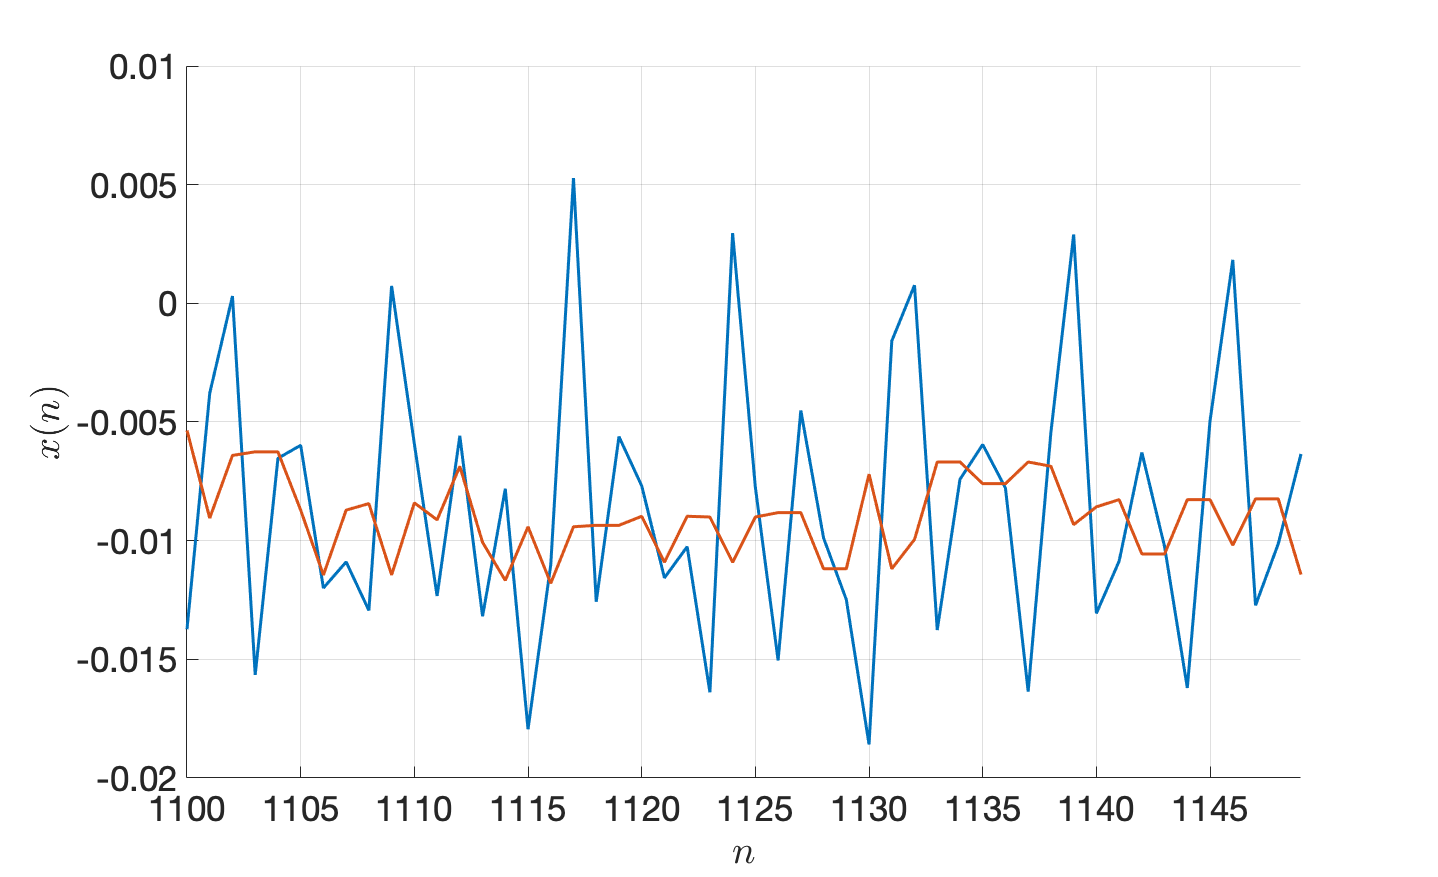

ti = 1100;%length(signal)/2;
Nsamples = 50; 
figure('units','normalized','outerposition',[0 0 1 1]);
hold on;
grid on;
set(gca,'FontSize',35);
xlabel("$n$",'Interpreter','latex');
ylabel("$x(n)$",'Interpreter','latex');
plot(ti:ti+Nsamples-1,signal(ti:ti+Nsamples-1),'LineWidth',3);
plot(ti:ti+Nsamples-1,signalMedianfilter(ti:ti+Nsamples-1),'LineWidth',3);
xlim([ti ti+Nsamples-1]);
saveas(gcf,'./figures/R3e_smallAmp.png');

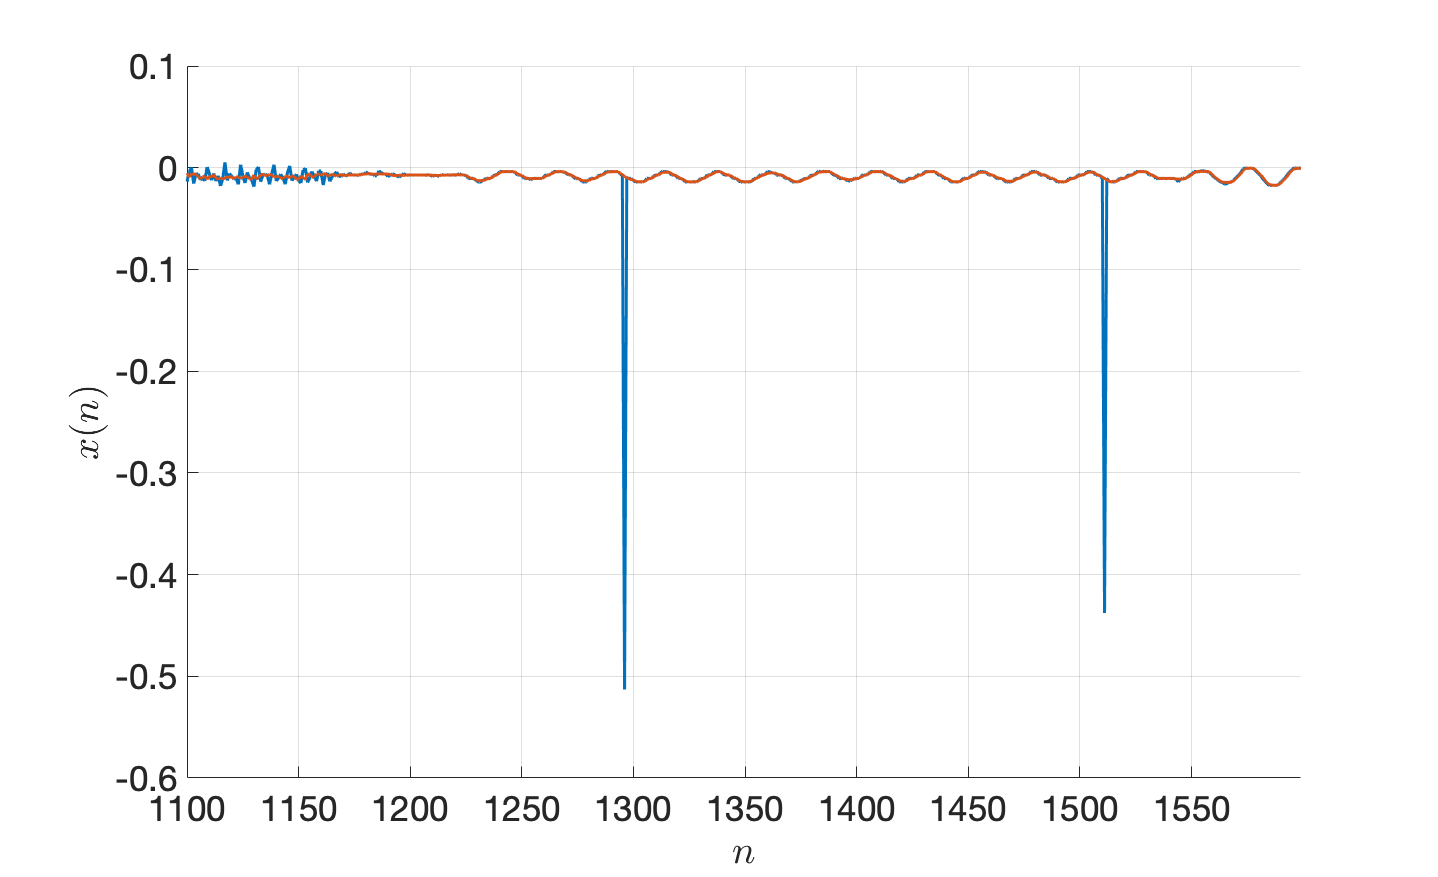

ti = 1100;%length(signal)/2;
Nsamples = 500; 
figure('units','normalized','outerposition',[0 0 1 1]);
hold on;
grid on;
set(gca,'FontSize',35);
xlabel("$n$",'Interpreter','latex');
ylabel("$x(n)$",'Interpreter','latex');
plot(ti:ti+Nsamples-1,signal(ti:ti+Nsamples-1),'LineWidth',3);
plot(ti:ti+Nsamples-1,signalMedianfilter(ti:ti+Nsamples-1),'LineWidth',3);
xlim([ti ti+Nsamples-1]);
saveas(gcf,'./figures/R3e_zoomNoise.png');

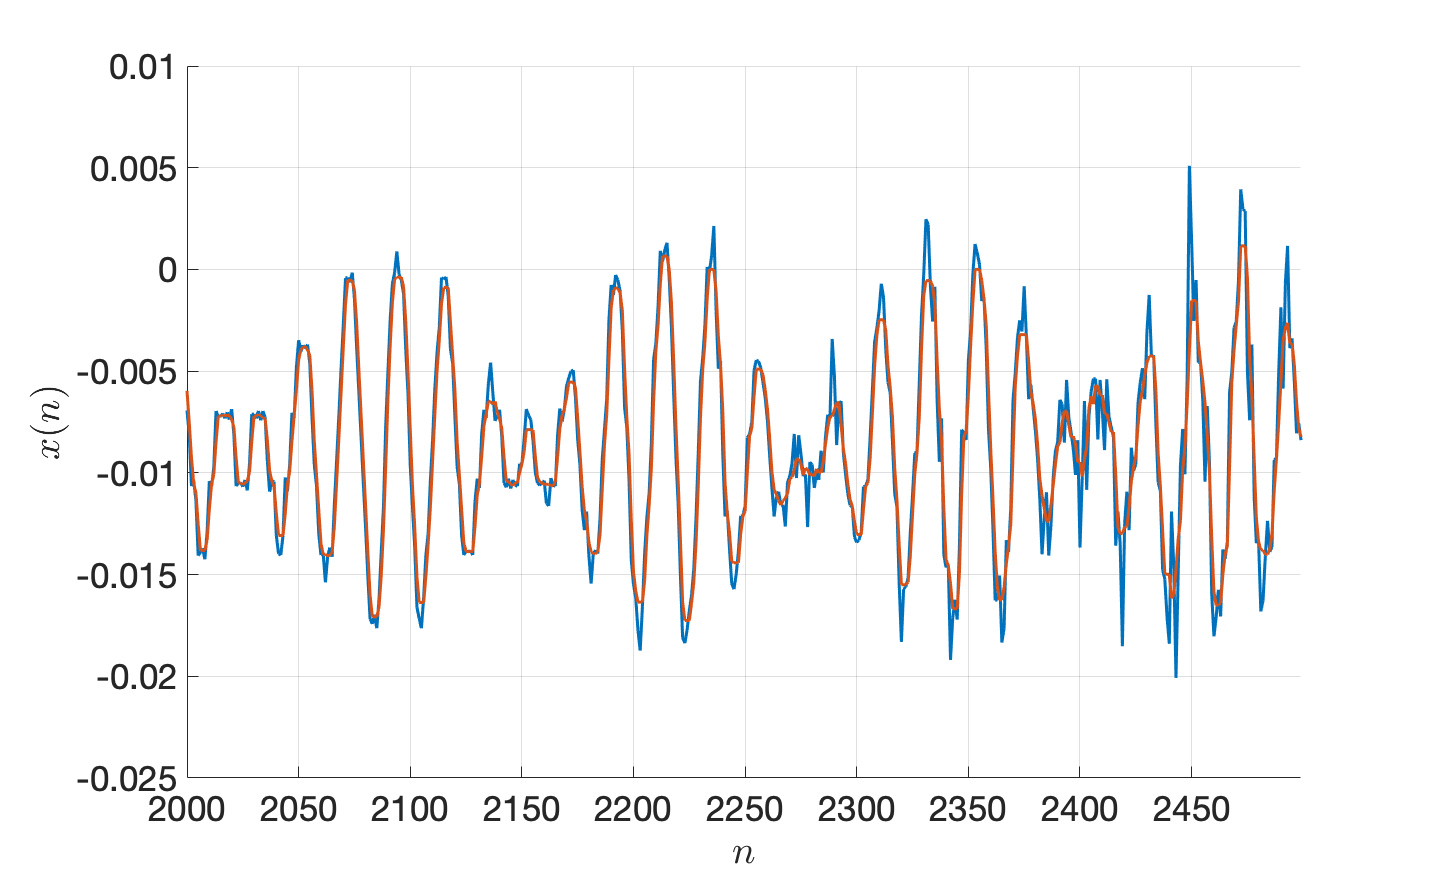

ti = 2000;%length(signal)/2;
Nsamples = 500; 
figure('units','normalized','outerposition',[0 0 1 1]);
hold on;
grid on;
set(gca,'FontSize',35);
xlabel("$n$",'Interpreter','latex');
ylabel("$x(n)$",'Interpreter','latex');
plot(ti:ti+Nsamples-1,signal(ti:ti+Nsamples-1),'LineWidth',3);
plot(ti:ti+Nsamples-1,signalMedianfilter(ti:ti+Nsamples-1),'LineWidth',3);
xlim([ti ti+Nsamples-1]);
saveas(gcf,'./figures/R3e_zoomNormal.png');

First, the sharp noises are also very attenuated, there is no difference in relation to order 3. Second, low aplitude regions are somewhat distorted, more than for order 3. Also in the last plot it is noticeabkle that the signal is not as sharp. Third, there are no visible oscilations due to the sharp noises. 

soundsc(signalMedianfilter,fs);

clear sound;

The signal is less sharp than for order 3. The sharp noises are also not heard. Givern that the sahrp noise are impulsive, a 3 order median is enugh to completely attenuate them. On the other hand, the higher the order the higher the distortion caused by median of a larger window causing loss of sharpness of the audio signal. Thus, an order of 3 is the best choice.

## R3.f)

The median filter, because it distinguishes between noise and signal due to the characteristics of the noise (impulsive). Contrarily, the LTI filter, attenuated high freqeuncy regardless of beig part of the signal or noise. For this reason, it is not possible to archieve a satisbfactory balance between sharpness and noise attenuation for the LTI filter. Thu, for the particular case of impulsiv noise a median filter of order 3 is shown to be the best choice among those studied.

## Dúvidas:

- delay medan

- o melhor é mesmo median de ordem 3, certo?

- loss of sharpness vem de onde?